# Electrode Grid and Retina Reference Grid

This file contains five parts:

Part 1 - Parametric electrode grid, drawn to scale (um)

Part 2 - Retina reference grid (degrees of visual angle)

Part 3 - Electrode grid placed on the retina grid

Part 4 - Image to phosphenes (scoreboard model)

Part 5 - Phosphenes placed in the retina frame

Part 6 - Ganglion cell axon trajectories

Part 7 - Axon map model

Part 8 - Parametric study of rho and lambda using *axon_map_model*

PART 9 - Comparison with pulse2percept

The calculations are done by functions defined at the END of this

file (local functions, MATLAB R2016b or later):

create_electrode_grid, place_grid_on_retina, draw_retina_grid,

sample_image_on_grid, render_phosphenes

To use it as a Live Script: Live Editor > Save As > "MATLAB Live Code File (*.mlx)".

clear; clc; close all;

## Electrode grid parameters (declared once)

These parameters are shared by Part 1, Part 3 and Part 4.

Edit them here only.

% --- Electrode grid (lengths in um) ---
nRows    = 16;             % Number of electrodes (rows)
nCols    = 16;             % Number of electrodes (columns)
pitchX   = 500;            % Center-to-center spacing along X [um]
pitchY   = 500;            % Center-to-center spacing along Y [um]
elecDiam = 250;             % Electrode diameter [um]
layout   = "square";       % "square" or "hexagonal"

% --- Electrode dropout model ---
dropoutPercent = 10;       % Percentage of electrodes that are non-functional [0-100]
dropoutSeed    = 42;       % Random seed: keeps the same failed electrodes between runs

% --- Retinal magnification (shared by Part 3 and Part 4) ---
umPerDeg = 288;            % 1 deg = 288 um


## Part 1 - Parametric electrode grid

This part defines the grid parameters and displays the array to scale.

All lengths are expressed in micrometers (um).

%% 1.1 User parameters
% Edit the values below (or replace them with Live Editor controls:
% Insert > Control > Numeric Slider / Drop-Down).

% The electrode grid parameters (nRows, nCols, pitchX, pitchY, elecDiam,
% layout) are declared once at the top of this file.
% "hexagonal" layout shifts every other row by half a pitch.

centerGrid = true;      % true  -> the grid is centered on the origin (0,0)
                        % false -> the first electrode is placed at the origin

%% 1.2 Overlap check
% The function does not know the electrode diameter, so this check is
% done here. Electrodes overlap if the diameter exceeds the smallest pitch.

if elecDiam > min(pitchX, pitchY)
    warning("Electrode diameter (%.0f um) exceeds the smallest pitch " + ...
            "(%.0f um): electrodes will overlap.", ...
            elecDiam, min(pitchX, pitchY));
end

%% 1.3 Create the electrode grid (function call)
% create_electrode_grid validates the inputs and returns:
%   x, y   : column vectors of electrode centers [um], numbered row by row
%   coords : table with columns Index, X_um, Y_um

[x, y, ~] = create_electrode_grid(nRows, nCols, pitchX, pitchY, ...
                                       layout, centerGrid);
nElec = numel(x);   % total number of electrodes

% Generate ONE dropout mask shared by every part of this script.
% dropoutMask(k) = true  -> electrode k is functional
% dropoutMask(k) = false -> electrode k has failed and cannot create a phosphene
assert(dropoutPercent >= 0 && dropoutPercent <= 100, ...
       "dropoutPercent must be between 0 and 100.");

rng(dropoutSeed, 'twister');                 % reproducible random selection
nFailed = round(nElec * dropoutPercent / 100);
failedIdx = randperm(nElec, nFailed);        % random electrode indices
dropoutMask = true(nElec, 1);
dropoutMask(failedIdx) = false;
nFunctional = nnz(dropoutMask);

fprintf('Electrode dropout : %.1f%% (%d/%d electrodes failed; %d functional)\\n', ...
        dropoutPercent, nFailed, nElec, nFunctional);

Electrode dropout : 10.0% (26/256 electrodes failed; 230 functional)\n

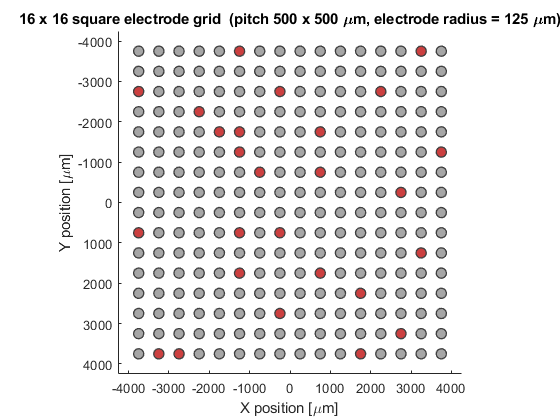


%% 1.4 Display the grid
% Each electrode is drawn as a circle of true diameter (in um), so the
% figure shows the real geometry of the array, including any overlap.

figure('Name', 'Electrode grid', 'Color', 'w');
ax = axes; hold(ax, 'on');

r = elecDiam / 2;   % electrode radius [um]

for k = 1:nElec
    % Functional electrodes are gold; failed electrodes are red.
    if dropoutMask(k)
        faceColor = [0.65 0.65 0.65];
    else
        faceColor = [0.80 0.25 0.25];
    end

    rectangle(ax, ...
        'Position',  [x(k)-r, y(k)-r, elecDiam, elecDiam], ...
        'Curvature', [1 1], ...
        'FaceColor', faceColor, ...
        'EdgeColor', [0.25 0.25 0.25], ...
        'LineWidth', 1);
end

axis(ax, 'equal');   % same scale on X and Y -> circles stay circular
axis(ax, 'ij');      % origin at the upper-left corner, Y axis pointing down
                     % (use axis(ax, 'xy') for the standard Cartesian view)
%grid(ax, 'on');
%box(ax, 'on');

% Add a margin of one pitch around the array so nothing touches the border.
margin = max(pitchX, pitchY);
xlim(ax, [min(x) - margin, max(x) + margin]);
ylim(ax, [min(y) - margin, max(y) + margin]);

xlabel(ax, 'X position [\mum]');
ylabel(ax, 'Y position [\mum]');
title(ax, sprintf('%d x %d %s electrode grid  (pitch %g x %g \\mum, electrode radius = %g \\mum)', ...
      nRows, nCols, layout, pitchX, pitchY, r));

##  Part 2 - Retina reference grid

This part draws a polar reference grid of the retina, expressed in degrees of visual angle and centered on the fovea.

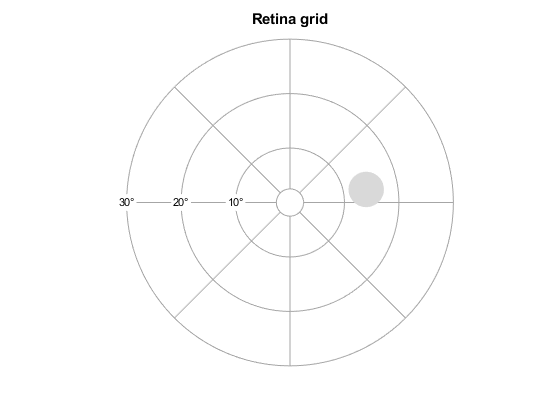

%% 2.1 User parameters
% All values are in degrees of visual angle.

maxEcc      = 30;           % Outermost eccentricity circle [deg]
eccStep     = 10;           % Spacing between concentric circles [deg]
angStep     = 45;           % Angle between radial lines [deg]

odCenter    = [14, 2.4];  % Optic disc center [x y] relative to the fovea [deg]
odSize      = [6.5, 6.5];   % Optic disc [width height] [deg]

foveaRadius = 2.5;          % Radius of the fovea marker [deg]

%% 2.2 Draw the retina grid (function call)
% The fovea is at the origin (0, 0). X points right, Y points up.

figure('Name', 'Retina reference grid', 'Color', 'w');
ax = axes;

draw_retina_grid(ax, maxEcc, eccStep, angStep, odCenter, odSize, foveaRadius);

title(ax, sprintf('Retina grid'));

## Part 3 - Electrode grid on the retina

This part builds an electrode grid, rotates it, places it at a given distance from the fovea, and draws it on the retina reference grid.

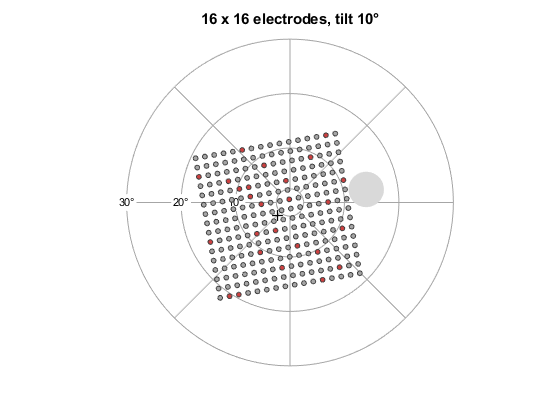

%% 3.1 User parameters

% The electrode grid (nRows, nCols, pitchX, pitchY, elecDiam, layout) and
% umPerDeg are declared once at the top of this file.

% --- Placement on the retina ---
centerOffset = [-650, -700];   % Array center relative to the fovea [x y] [um]
                               % X to the right, Y up
tiltDeg      = 10;              % Array rotation around its center [deg]
                               % positive = counter-clockwise

% --- Retina grid (degrees of visual angle) ---
maxEcc      = 30;           % Outermost eccentricity circle [deg]
eccStep     = 10;           % Spacing between concentric circles [deg]
angStep     = 45;           % Angle between radial lines [deg]


%% 3.2 Create the electrode grid (function call)
% The grid is centered on its own origin so that the rotation and the
% placement are applied around the array center (last argument = true), so
% centerOffset is the position of the array center.

[x, y, coords] = create_electrode_grid(nRows, nCols, pitchX, pitchY, ...
                                       layout, true);
nElec = numel(x);

%% 3.3 Place the grid on the retina (function call)
% Flip Y, rotate by tiltDeg, translate by centerOffset, convert um -> degrees.

[xDeg, yDeg] = place_grid_on_retina(x, y, centerOffset, tiltDeg, umPerDeg);

% Useful numbers
centerDeg   = centerOffset / umPerDeg;        % array center [deg]
distanceUm  = norm(centerOffset);             % fovea-to-array distance [um]
distanceDeg = distanceUm / umPerDeg;          % same distance [deg]
elecDiamDeg = elecDiam / umPerDeg;            % electrode diameter [deg]

% Warn if some electrodes fall outside the drawn retina
if any(hypot(xDeg, yDeg) > maxEcc)
    warning("Some electrodes are beyond the outer circle (%g deg).", maxEcc);
end

%% 3.4 Display
% Draw the retina grid first (function call), then each electrode as a
% circle of true size.

figure('Name', 'Electrode grid on the retina', 'Color', 'w');
ax = axes;

draw_retina_grid(ax, maxEcc, eccStep, angStep, odCenter, odSize, foveaRadius);

r = elecDiamDeg / 2;   % electrode radius [deg]
for k = 1:nElec
    % --- CONDITION: Skip drawing if the electrode is outside the retina circle ---
    if hypot(xDeg(k), yDeg(k)) > maxEcc
        continue; 
    end

    % Use exactly the same dropout selection as in Part 1.
    if dropoutMask(k)
        faceColor = [0.65 0.65 0.65];
    else
        faceColor = [0.80 0.25 0.25];
    end

    rectangle(ax, ...
        'Position',  [xDeg(k)-r, yDeg(k)-r, elecDiamDeg, elecDiamDeg], ...
        'Curvature', [1 1], ...
        'FaceColor', faceColor, ...
        'EdgeColor', [0.25 0.25 0.25], ...
        'LineWidth', 0.75);
end

% Mark the array center with a cross
plot(ax, centerDeg(1), centerDeg(2), 'k+', 'MarkerSize', 8, 'LineWidth', 1);

title(ax, sprintf(['%d x %d electrodes, tilt %g%c' ...
      '%.0f \\mum (%.1f%c)'], nRows, nCols, tiltDeg, char(176)));

## Part 4 - Image to phosphenes (scoreboard model)

Takes an image as input and displays the phosphenes that an electrode grid would produce. Pipeline:

   1. electrode grid [um] -> visual angle [deg]  (288 um = 1 deg)

   2. image mapped onto the field of view of the grid

   3. mean intensity at each electrode (box filter = electrode spacing)

   4. quantization to a few gray levels

   5. levels -> stimulation current (0 to 120 uA)

   6. current -> brightness with B = a * C^b

   7. each electrode drawn as a Gaussian phosphene (sigma = sigmaFactor * D)

   8. display: input image and phosphenes (electrodes are NOT drawn)

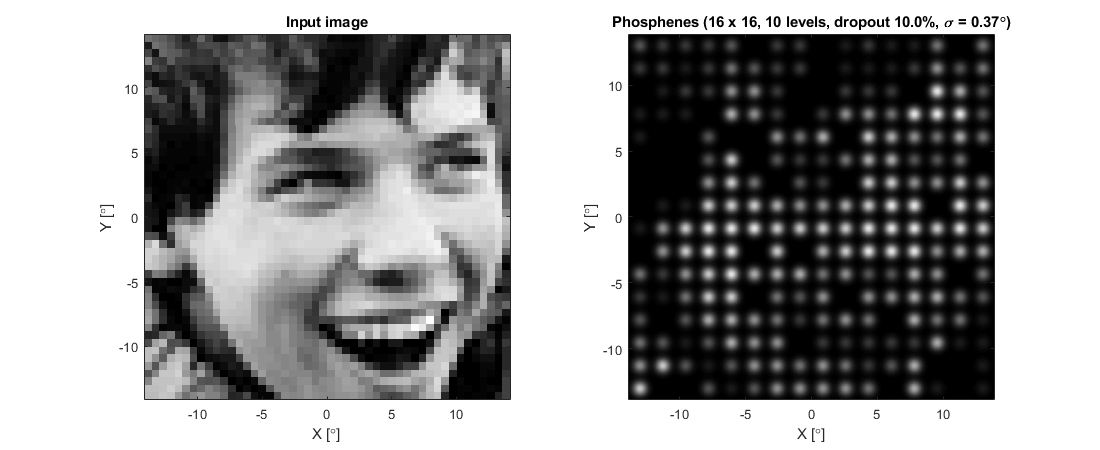

%% 4.1 User parameters

% --- Input image ---
imgFile          = "E:\Documents\Etudes\MVR\Sujet recherche\simulation\SmileTest_1.jpg";     % path to a grayscale or RGB image; '' = synthetic test image
cropToGridAspect = true;   % true -> center-crop the image to the grid's aspect ratio
                           % (avoids deforming the image when it is stretched on the grid)

% The electrode grid (nRows, nCols, pitchX, pitchY, elecDiam, layout) and
% umPerDeg are declared once at the top of this file.

% --- Quantization and stimulation ---
nLevels  = 10;             % Number of gray levels: 2, 4, 8 or 10
Cmax     = 120;            % Current for the brightest level [uA] (range 0 to Cmax)

% --- Brightness model B = a * C^b ---
a = 1.24;
b = 1.02;

% --- Phosphene rendering ---
sigmaFactor    = 0.425;        % sigma = sigmaFactor * D  (D = electrode diameter [deg])

% --- Output image rendering ---
outRes = 60;       % Resolution of the output image [pixel/deg]

assert(nLevels >= 2 && nLevels == round(nLevels), "The gray level must be an integer >= 2.");

%% 4.2 Electrode grid in degrees of visual angle

%[x, y] is the electrode grid created in µm
%[xDeg, yDeg] electrode corrdinate in degrees of visual angle
xDeg =  x / umPerDeg;
yDeg = -y / umPerDeg;

pitchXDeg    = pitchX   / umPerDeg;    % electrode spacing [deg]
pitchYDeg    = pitchY   / umPerDeg;
elecDiamDeg  = elecDiam / umPerDeg;    % electrode diameter [deg]

% Field of view covered by the grid: distance between the outer electrode
% centers plus one pitch, so that each electrode owns a full cell.
widthDeg  = (max(xDeg) - min(xDeg)) + pitchXDeg;
heightDeg = (max(yDeg) - min(yDeg)) + pitchYDeg;

nElec = numel(xDeg);

%% 4.3 Load the input image (grayscale, values in [0, 1])

if ~isempty(imgFile) && isfile(imgFile)
    raw = imread(imgFile);
    if isinteger(raw)
        img = double(raw) / double(intmax(class(raw)));   % uint8 -> [0, 1]
    else
        img = double(raw);
    end
    if size(img, 3) >= 3                                   % RGB -> gray (luminance)
        img = 0.299*img(:,:,1) + 0.587*img(:,:,2) + 0.114*img(:,:,3);
    else
        img = img(:,:,1);
    end
else
    if ~isempty(imgFile)
        warning("File '%s' not found: using the synthetic test image.", imgFile);
    end
    % Synthetic 240 x 240 test image: horizontal ramp + bright disc.
    [X, Y] = meshgrid(linspace(-1, 1, 240));
    img = 0.5 * (X + 1) / 2;
    img(X.^2 + Y.^2 < 0.4^2) = 1;
end

%% 4.4 Map the image onto the grid
% The image is stretched over the field of view of the grid. To keep the
% proportions, the image is first center-cropped to the grid's aspect ratio.

if cropToGridAspect
    [H, W] = size(img);
    target = widthDeg / heightDeg;              % grid aspect ratio (width / height)
    if W / H > target                           % image too wide -> crop columns
        Wn = round(H * target);
        c0 = floor((W - Wn) / 2) + 1;
        img = img(:, c0:c0+Wn-1);
    else                                        % image too tall -> crop rows
        Hn = round(W / target);
        r0 = floor((H - Hn) / 2) + 1;
        img = img(r0:r0+Hn-1, :);
    end
end

%% 4.5 Mean intensity at each electrode (function call)
% Electrode -> nearest pixel; intensity = box-filter mean whose size is the
% electrode spacing converted to pixels (rounded to an odd number).

[I, ~, ~, pxPerDeg, filtSize] = sample_image_on_grid(img, xDeg, yDeg, ...
                                    pitchXDeg, pitchYDeg, widthDeg, heightDeg);

%% 4.6 Quantization
% Map the mean intensity [0, 1] to nLevels equally spaced values in [0, 1].

Iq = round(I * (nLevels - 1)) / (nLevels - 1);

%% 4.7 Stimulation current and brightness
% Quantized level -> current between 0 and Cmax, then B = a * C^b.
% B is normalized by its value at Cmax so that the brightest level is 1
% (white); level 0 gives C = 0, hence no phosphene.

C    = Iq * Cmax;               % current of each electrode [uA]
B    = a * C.^b;                % brightness (rating units)
Bmax = a * Cmax^b;              % brightness at the maximum current
Bn   = B / Bmax;                % normalized brightness in [0, 1]

% Electrode failure overrides the image-derived brightness.
% A failed electrode produces no phosphene, even if its pixel is white.
Bn(~dropoutMask) = 0;

%% 4.8 Render the phosphenes (function call)
% Gaussian phosphenes, sigma = sigmaFactor * D.

sigmaDeg = sigmaFactor * elecDiamDeg;
[P, xg, yg] = render_phosphenes(xDeg, yDeg, Bn, sigmaDeg, widthDeg, heightDeg, outRes);

%% 4.9 Display: input image (left) and phosphenes (right)
% Electrodes are not drawn, only the resulting phosphenes.

figure('Name', 'Phosphene simulation', 'Color', 'w', 'Position', [100 100 1100 450]);

ax1 = subplot(1, 2, 1);
imagesc(ax1, [-widthDeg/2 widthDeg/2], [heightDeg/2 -heightDeg/2], img);
set(ax1, 'YDir', 'normal', 'CLim', [0 1]);   % Y up, image upright
colormap(ax1, 'gray'); axis(ax1, 'image');
xlabel(ax1, 'X [\circ]'); ylabel(ax1, 'Y [\circ]');
title(ax1, 'Input image');

ax2 = subplot(1, 2, 2);
imagesc(ax2, [xg(1) xg(end)], [yg(1) yg(end)], P);
set(ax2, 'YDir', 'normal', 'CLim', [0 1], 'Color', 'k');
colormap(ax2, 'gray'); axis(ax2, 'image');
xlabel(ax2, 'X [\circ]'); ylabel(ax2, 'Y [\circ]');
title(ax2, sprintf('Phosphenes (%d x %d, %d levels, dropout %.1f%%, \\sigma = %.2f\\circ)', ...
      nRows, nCols, nLevels, dropoutPercent, sigmaDeg));

%% 4.10 Summary

fprintf('Field of view      : %.2f x %.2f deg\n', widthDeg, heightDeg);

Field of view      : 27.78 x 27.78 deg


fprintf('Image resolution   : %.1f (X) x %.1f (Y) pixel/deg\n', pxPerDeg(1), pxPerDeg(2));

Image resolution   : 1.7 (X) x 1.7 (Y) pixel/deg


fprintf('Box filter size    : %d x %d pixels (odd)\n', filtSize(1), filtSize(2));

Box filter size    : 3 x 3 pixels (odd)


fprintf('Gaussian sigma     : %.3f deg (D = %.3f deg)\n', sigmaDeg, elecDiamDeg);

Gaussian sigma     : 0.369 deg (D = 0.868 deg)


fprintf('Brightness at Cmax : B = %.1f (used to normalize to 1)\n', Bmax);

Brightness at Cmax : B = 163.8 (used to normalize to 1)



isFunctional = dropoutMask;
results = table((1:nElec)', xDeg, yDeg, isFunctional, I, Iq, C, Bn, ...
    'VariableNames', {'Index', 'X_deg', 'Y_deg', 'Functional', 'MeanIntensity', ...
                      'Quantized', 'Current_uA', 'Brightness'});
disp(head(results, 20));

    Index     X_deg      Y_deg     Functional    MeanIntensity    Quantized    Current_uA    Brightness
    _____    ________    ______    __________    _____________    _________    __________    __________

      1       -13.021    13.021      true           0.32549        0.33333           40       0.32609  
      2       -11.285    13.021      true           0.26449        0.22222       26.667       0.21564  
      3       -9.5486    13.021      true           0.25403        0.22222       26.667       0.21564  
      4       -7.8125    13.021      true           0.23355        0.22222       26.667       0.21564  
      5       -6.0764    13.021      true           0.34074        0.33333           40       0.32609  

### Part 5 - Phosphenes in the retina frame

The phosphenes computed in Part 4 are placed at the retinal position oftheir electrode,

i.e. the position of the grid on the retina set in Part 3 (centerOffset and tiltDeg). Everything that is not a phosphene is black, and the retina reference grid is NOT drawn.

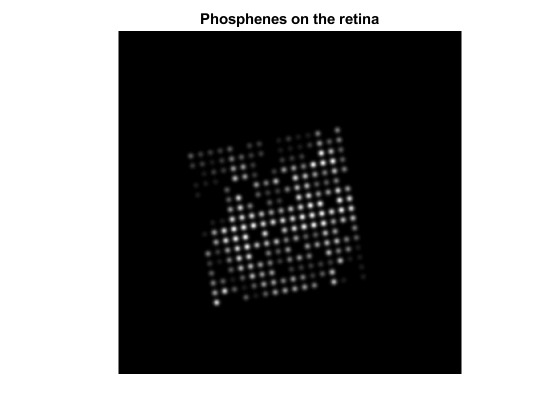

%% 5.1 Parameters
showAxes       = false;    % true -> show the X/Y axes in degrees (still no retina grid)

% The displayed field of view is the square [-maxEcc, maxEcc] x [-maxEcc, maxEcc]
% centered on the fovea (maxEcc, centerOffset and tiltDeg come from Part 3).

%% 5.2 Electrode positions on the retina & Retinal Masking
% Part 4 expressed the electrodes in the grid's own frame (centered, no tilt).
% Here the SAME electrodes (same order, so same brightness Bn) are placed with
% the offset and the tilt of Part 3. x and y [um] come from Part 4.

[xRet, yRet] = place_grid_on_retina(x, y, centerOffset, tiltDeg, umPerDeg);

% --- Mask to exclude electrodes outside the retina reference circle (maxEcc) ---
insideRetinaMask = hypot(xRet, yRet) <= maxEcc;

% Apply mask: zero out brightness for electrodes outside the retina boundary
Bn_retina = Bn; 
Bn_retina(~insideRetinaMask) = 0;

% Warn if some phosphenes fall outside the displayed field of view
nOutside = nnz(~insideRetinaMask);
if nOutside > 0
    warning("%d electrodes are outside the retina circle (%g deg) and their phosphenes have been masked.", ...
        nOutside, maxEcc);
end

%% 5.3 Render the phosphenes on the retina (function call)
% Same Gaussian phosphenes as in Part 4 (same sigma and brightness), on a
% black canvas covering the retina. Outside electrodes have 0 brightness and won't render.

[Pret, xr, yr] = render_phosphenes(xRet, yRet, Bn_retina, sigmaDeg, ...
                                   2*maxEcc, 2*maxEcc, outRes);

%% 5.4 Display
% Only the phosphenes are shown (electrodes and retina grid are not drawn).

figure('Name', 'Phosphenes on the retina', 'Color', 'w');
ax = axes;

imagesc(ax, [xr(1) xr(end)], [yr(1) yr(end)], Pret);
set(ax, 'YDir', 'normal', 'CLim', [0 1]);   % Y up, same convention as the retina grid
colormap(ax, 'gray'); axis(ax, 'image');

if showAxes
    xlabel(ax, 'X [\circ]'); ylabel(ax, 'Y [\circ]');
else
    axis(ax, 'off');
end

title(ax, sprintf(['Phosphenes on the retina']));

### Part 6 - Ganglion cell axon trajectories

% Uses from earlier parts: umPerDeg, xRet, yRet, Bn_retina (Part 5),
% eccStep, angStep, odSize, foveaRadius (Part 2), and the local functions
% draw_retina_grid and render_phosphenes.
% Coordinates are in degrees of visual angle, origin = fovea.

%% 6.1 User parameters

axonODCenter = [14, 2.4]; % Optic disc center relative to the fovea [deg]
maxDegrees   = 30; % Maximum retinal eccentricity [deg]

rStart  = 4.01; % Initial distance from the optic disc center [deg]
rMax    = 60;  % Safety bound on the radial distance [deg]
deltaR  = 0.1; % Radial increment [deg]

% DENSE bundle: the axon map needs many axons so that every retinal
% location (= possible soma) lies close to one axon.
% As a reference pulse2percept uses 500 axons with phi0 in [-180, 180].
nAxons = 500;
phi0sequence = linspace(-180, 180, nAxons);

% Display parameters (only 1 axon out of plotStride is drawn)
plotStride = 10;
axonColor = [0.2 0.2 0.2];
axonLineWidth = 0.75;

%% 6.2 Generate or load axon trajectories (cached)

axonCacheFile = fullfile(pwd, 'axon_trajectories_cache.mat');

axonCacheMeta = struct( ...
    'phi0sequence', phi0sequence(:).', ...
    'rStart', rStart, 'rMax', rMax, 'deltaR', deltaR, ...
    'axonODCenter', axonODCenter, 'maxDegrees', maxDegrees, ...
    'version', 2);

useAxonCache = false;
if isfile(axonCacheFile)
    S = load(axonCacheFile, 'axonPaths', 'axonCacheMeta');
    if isfield(S, 'axonPaths') && isfield(S, 'axonCacheMeta') && ...
       isequaln(S.axonCacheMeta, axonCacheMeta)
        axonPaths    = S.axonPaths;
        useAxonCache = true;
        fprintf('Axon trajectories loaded from cache.\n');
    end
end

Axon trajectories loaded from cache.


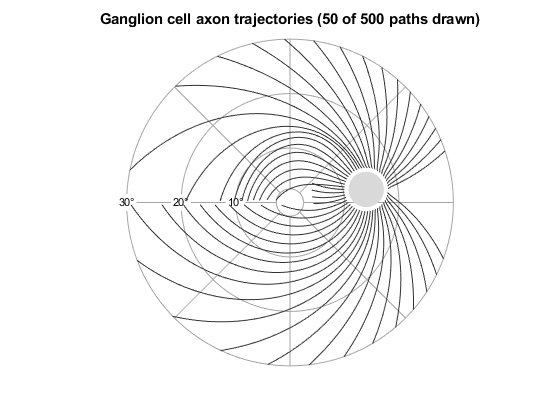


if ~useAxonCache
    fprintf('Calculating %d axon trajectories...\n', nAxons);
    axonPaths = cell(nAxons, 1);

    for k = 1:nAxons
        phi0 = phi0sequence(k);

        % Whole trajectory at once (vectorized over r)
        r   = (rStart:deltaR:rMax).';
        phi = jansonius_phi(phi0, r);
        xs  = r .* cosd(phi) + axonODCenter(1);
        ys  = r .* sind(phi) + axonODCenter(2);

        % Stopping rules (same as before)
        if phi0 > 0
            stop = (ys <= 0.5);                    % superior fibers
        else
            stop = (ys >= -0.5) & (r > 10);        % inferior fibers
        end
        stop = stop | (xs.^2 + ys.^2 > maxDegrees^2);  % outside the retina

        iEnd = find(stop, 1, 'first');
        if isempty(iEnd), iEnd = numel(r); end

        axonPaths{k} = [xs(1:iEnd), ys(1:iEnd)];
    end

    save(axonCacheFile, 'axonPaths', 'axonCacheMeta');
    fprintf('Axon trajectories saved to: %s\n', axonCacheFile);
end

%% 6.3 Display (subset of the trajectories)

figure('Name', 'Jansonius axon trajectories', 'Color', 'w');
ax = axes;
draw_retina_grid(ax, maxDegrees, eccStep, angStep, axonODCenter, odSize, foveaRadius);
hold(ax, 'on');
for k = 1:plotStride:nAxons
    xy = axonPaths{k};
    plot(ax, xy(:,1), xy(:,2), 'Color', axonColor, 'LineWidth', axonLineWidth);
end
title(ax, sprintf('Ganglion cell axon trajectories (%d of %d paths drawn)', ...
      numel(1:plotStride:nAxons), nAxons));

### Part 7 - Axon map model (Beyeler et al. 2019)

For a soma located at (x, y), the axon is the fiber passing through that point. The brightness of that soma is

  I(soma) = max over upstream segments i of

            [ sum_e amp_e * exp(-d_e(i)^2 / (2 rho^2)) ] * exp(-s(i,soma)/lambda)

  d_e(i)     : Euclidean distance between segment i and electrode e

  s(i,soma)  : path length along the axon between segment i and the soma

  rho        : spread around the electrode (Gaussian, like the scoreboard)

  lambda     : decay along the axon (EXPONENTIAL in Beyeler 2019)

Every retinal pixel is a possible soma and is assigned to its NEAREST

axon sample (as find_closest_axon does in pulse2percept).

%% 7.1 Parameters
rhoDeg = sigmaFactor * elecDiamDeg;  % Spread around the electrode [deg]
lambdaUm = 200;     % Axon length constant [um]
lambdaDeg = lambdaUm / umPerDeg;  % convert labda to visual angle degre

decayModel = "gaussian";    % "exponential" (Beyeler 2019) or gaussian
axonStep   = 0.1;    % Arc-length sampling along the axons [deg]
mapRes     = 20;   % Resolution of the output image [pixel/deg]
maxSnapDeg = 0.75;   % A pixel farther than this from every axon stays black [deg]
showElectrodes = false; % Overlay the electrode centers on the figure
fprintf('rho = %.3f deg, lambda = %.3f deg (%s decay)\n', rhoDeg, lambdaDeg, decayModel);

rho = 0.369 deg, lambda = 0.694 deg (gaussian decay)


%% 7.2 Resample the trajectories by arc length (cached)
% The cache only depends on the axon geometry (not on the image size or on
% the electrodes), so it stays valid when you change the stimulus.

axonSampleCacheFile = fullfile(pwd, 'axon_sampling_cache_v3.mat');

axonSampleCacheMeta = struct( ...
    'axonCacheMeta', axonCacheMeta, 'axonStep', axonStep, 'version', 3);

useSampleCache = false;
if isfile(axonSampleCacheFile)
    S = load(axonSampleCacheFile, 'axonSampleX', 'axonSampleY', ...
             'axonSampleS', 'axonSampleCacheMeta');
    if isfield(S, 'axonSampleCacheMeta') && ...
       isequaln(S.axonSampleCacheMeta, axonSampleCacheMeta)
        axonSampleX = S.axonSampleX;
        axonSampleY = S.axonSampleY;
        axonSampleS = S.axonSampleS;
        useSampleCache = true;
        fprintf('Axon samples loaded from cache.\n');
    end
end

Axon samples loaded from cache.



if ~useSampleCache
    fprintf('Resampling axon trajectories...\n');
    nAx = numel(axonPaths);
    axonSampleX = cell(nAx, 1);
    axonSampleY = cell(nAx, 1);
    axonSampleS = cell(nAx, 1);

    for k = 1:nAx
        xy = axonPaths{k};
        s  = [0; cumsum(hypot(diff(xy(:,1)), diff(xy(:,2))))];  % path length from the start [deg]
        [s, u] = unique(s, 'stable');
        xF = xy(u,1);  yF = xy(u,2);
        if numel(s) < 2, continue; end

        sQ = (0:axonStep:s(end)).';
        if sQ(end) < s(end), sQ(end+1) = s(end); end

        axonSampleX{k} = interp1(s, xF, sQ, 'linear');
        axonSampleY{k} = interp1(s, yF, sQ, 'linear');
        axonSampleS{k} = sQ;       % distance from the optic-disc end of the axon
    end

    save(axonSampleCacheFile, 'axonSampleX', 'axonSampleY', ...
         'axonSampleS', 'axonSampleCacheMeta');
    fprintf('Axon sample cache saved.\n');
end

%% 7.3 Activation of every possible soma along every axon

nAx = numel(axonSampleS);

% Only electrodes that can produce a phosphene and also removes failed ones
% and the ones masked outside the retina in Part 5.
act = Bn_retina > 0;
xe  = xRet(act);  ye = yRet(act);  ae = Bn_retina(act);

maxLag = ceil(5 * lambdaDeg / axonStep);   % only used by the "gaussian" model

cellX = cell(nAx, 1);
cellY = cell(nAx, 1);
cellI = cell(nAx, 1);

for k = 1:nAx
    xF = axonSampleX{k};
    yF = axonSampleY{k};
    s  = axonSampleS{k};
    n  = numel(s);
    if n < 2, continue; end

    % (a) Electrode term: sum of Gaussians (rho) at each axon sample.
    %     Computed directly: no clipping, no image interpolation.
    D2     = (xF - xe.').^2 + (yF - ye.').^2;        % n x nActiveElectrodes
    Iscore = exp(-D2 / (2 * rhoDeg^2)) * ae;

    % (b) Max over the upstream segments, weighted by the decay along the axon.
    Iax = Iscore;   % lag 0: stimulated point = soma
    switch decayModel
        case "exponential"
            % exp(-(sj-si)/lambda) = exp(-(sj-s(j-1))/lambda)*exp(-(s(j-1)-si)/lambda)
            % -> exact O(n) recursion instead of a loop over all lags.
            g = exp(-diff(s) / lambdaDeg);
            for j = 2:n
                Iax(j) = max(Iscore(j), Iax(j-1) * g(j-1));
            end
        case "gaussian"
            for lag = 1:min(n-1, maxLag)
                d = s(1+lag:n) - s(1:n-lag);
                Iax(1+lag:n) = max(Iax(1+lag:n), ...
                                   Iscore(1:n-lag) .* exp(-d.^2 / (2*lambdaDeg^2)));
            end
        otherwise
            error("decayModel must be ""exponential"" or ""gaussian"".");
        end

    cellX{k} = xF;  cellY{k} = yF;  cellI{k} = Iax;
end

allX = vertcat(cellX{:});
allY = vertcat(cellY{:});
allI = vertcat(cellI{:});

%% 7.4 Assign every retinal pixel to its nearest axon sample (soma = pixel)

xm = -maxDegrees : 1/mapRes : maxDegrees;
ym =  maxDegrees : -1/mapRes : -maxDegrees;      % row 1 = top
[XM, YM] = meshgrid(xm, ym);
q   = [XM(:), YM(:)];
pts = [allX, allY];

if license('test', 'Statistics_Toolbox') && exist('knnsearch', 'file')
    [idx, dist] = knnsearch(pts, q);             % KD-tree: fast
else
    idx  = dsearchn(pts, q);                     % base MATLAB: slower
    dist = hypot(pts(idx,1) - q(:,1), pts(idx,2) - q(:,2));
end

Paxon = reshape(allI(idx), size(XM));
Paxon(reshape(dist, size(XM)) > maxSnapDeg) = 0;   % no axon close enough
Paxon(hypot(XM, YM) > maxDegrees) = 0;             % outside the retina

%% 7.5 Scoreboard with the same rho (for comparison)

[Pscore, xs, ys] = render_phosphenes(xRet(act), yRet(act), ae, rhoDeg, ...
                                     2*maxDegrees, 2*maxDegrees, mapRes);

%% 7.6 Diagnostics

fprintf('Axon samples used      : %d\n', numel(allX));

Axon samples used      : 128288


fprintf('Max axonal activation  : %.4f\n', max(Paxon(:)));

Max axonal activation  : 0.8848


fprintf('Max scoreboard         : %.4f\n', max(Pscore(:)));

Max scoreboard         : 0.8868


fprintf('Non-zero pixels (axon) : %d\n', nnz(Paxon));

Non-zero pixels (axon) : 1057910


fprintf('Check: with lambda -> 0 the axon map must tend to the scoreboard.\n');

Check: with lambda -> 0 the axon map must tend to the scoreboard.


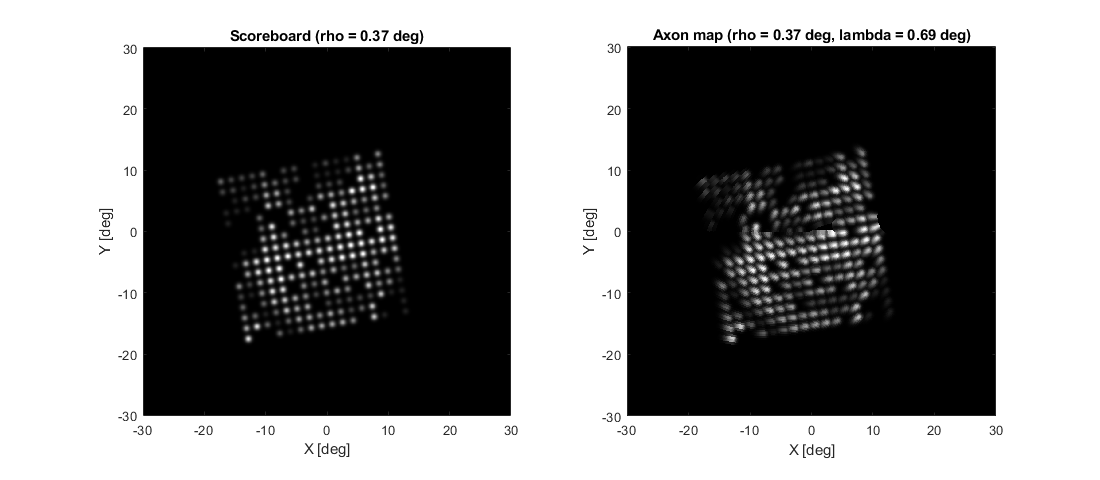


%% 7.7 Display: scoreboard (left) vs axon map (right)

cMax = max([Paxon(:); Pscore(:); eps]);

figure('Name', 'Scoreboard vs axon map', 'Color', 'w', 'Position', [100 100 1100 480]);

ax1 = subplot(1, 2, 1);
imagesc(ax1, xs, ys, Pscore);
set(ax1, 'YDir', 'normal', 'CLim', [0 cMax], 'Color', 'k');
colormap(ax1, gray(256)); axis(ax1, 'image');
xlabel(ax1, 'X [deg]'); ylabel(ax1, 'Y [deg]');
title(ax1, sprintf('Scoreboard (rho = %.2f deg)', rhoDeg));

ax2 = subplot(1, 2, 2);
imagesc(ax2, xm, ym, Paxon);
set(ax2, 'YDir', 'normal', 'CLim', [0 cMax], 'Color', 'k');
colormap(ax2, gray(256)); axis(ax2, 'image');
xlabel(ax2, 'X [deg]'); ylabel(ax2, 'Y [deg]');
title(ax2, sprintf('Axon map (rho = %.2f deg, lambda = %.2f deg)', rhoDeg, lambdaDeg));

### Part 8 - Parametric study of rho and lambda using *axon_map_model*


%% 8.1 Parameters (taken from the previous parts)

imgFile = "E:\Documents\Etudes\MVR\Sujet recherche\simulation\SmileTest_1.jpg";

tiltDeg = 0;
gridSize = [16, 16];
pitchUm = [500, 500];
retinaPos = [centerOffset, tiltDeg];

% Fixed model parameters
placeOnRetina = false;
dropoutPercent = 0;

% Parameters for the parametric study
rhoValues = [50, 100];       % Phosphene spread rho [um]
lambdaValues = [50, 200];    % Axon length constant lambda [um]

%% 8.2 Run the four Axon Map models

% Model 1: rho = 100 um, lambda = 100 um
axRes11 = axon_map_model(imgFile, gridSize, pitchUm, dropoutPercent, ...
                         retinaPos, rhoValues(1), lambdaValues(1), ...
                         'MapRes', 30, ...
                         'PlaceOnRetina', placeOnRetina);

Axon map: rho = 0.174 deg, lambda = 0.174 deg (gaussian decay)
Computing 1000 axon trajectories...
Axon samples saved to: axon_sampling_cache_fn.mat
Axon points: 259300 | max activation: 0.8867 | max scoreboard: 0.8864



% Model 2: rho = 200 um, lambda = 100 um
axRes12 = axon_map_model(imgFile, gridSize, pitchUm, dropoutPercent, ...
                         retinaPos, rhoValues(2), lambdaValues(1), ...
                         'MapRes', 30, ...
                         'PlaceOnRetina', placeOnRetina);

Axon map: rho = 0.347 deg, lambda = 0.174 deg (gaussian decay)
Axon samples loaded from cache.
Axon points: 259300 | max activation: 0.8868 | max scoreboard: 0.8867



% Model 3: rho = 100 um, lambda = 300 um
axRes21 = axon_map_model(imgFile, gridSize, pitchUm, dropoutPercent, ...
                         retinaPos, rhoValues(1), lambdaValues(2), ...
                         'MapRes', 30, ...
                         'PlaceOnRetina', placeOnRetina);

Axon map: rho = 0.174 deg, lambda = 0.694 deg (gaussian decay)
Axon samples loaded from cache.
Axon points: 259300 | max activation: 0.8867 | max scoreboard: 0.8864



% Model 4: rho = 200 um, lambda = 300 um
axRes22 = axon_map_model(imgFile, gridSize, pitchUm, dropoutPercent, ...
                         retinaPos, rhoValues(2), lambdaValues(2), ...
                         'MapRes', 30, ...
                         'PlaceOnRetina', placeOnRetina);

Axon map: rho = 0.347 deg, lambda = 0.694 deg (gaussian decay)
Axon samples loaded from cache.
Axon points: 259300 | max activation: 0.8868 | max scoreboard: 0.8867


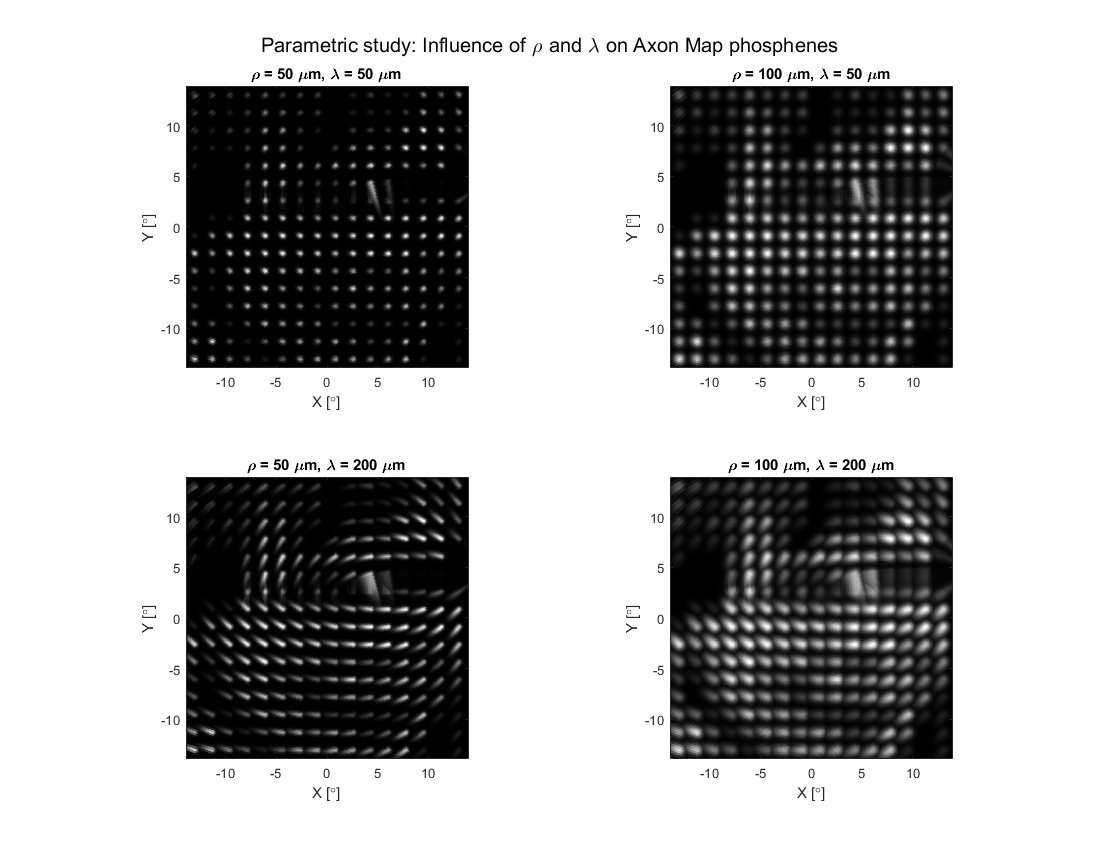


%% 8.3 Display the four Axon Map models in a 2x2 grid

figure('Name', 'Part 8 - Parametric study of Axon Map', ...
       'Color', 'w', ...
       'Position', [100 100 1100 850]);

% Common display scale for all four models
allMax = max([axRes11.Paxon(:); ...
              axRes12.Paxon(:); ...
              axRes21.Paxon(:); ...
              axRes22.Paxon(:)], [], 'omitnan');

if isempty(allMax) || ~isfinite(allMax) || allMax <= 0
    allMax = 1;
end

commonCLim = [0 allMax];

% Model 1: rho = 100 um, lambda = 100 um
ax1 = subplot(2, 2, 1);
imagesc(ax1, axRes11.xr, axRes11.yr, axRes11.Paxon);
set(ax1, 'YDir', 'normal', 'CLim', commonCLim, 'Color', 'k');
colormap(ax1, gray(256));
axis(ax1, 'image');
xlabel(ax1, 'X [\circ]');
ylabel(ax1, 'Y [\circ]');
title(ax1, '\rho = 50 \mum, \lambda = 50 \mum');

% Model 2: rho = 200 um, lambda = 100 um
ax2 = subplot(2, 2, 2);
imagesc(ax2, axRes12.xr, axRes12.yr, axRes12.Paxon);
set(ax2, 'YDir', 'normal', 'CLim', commonCLim, 'Color', 'k');
colormap(ax2, gray(256));
axis(ax2, 'image');
xlabel(ax2, 'X [\circ]');
ylabel(ax2, 'Y [\circ]');
title(ax2, '\rho = 100 \mum, \lambda = 50 \mum');

% Model 3: rho = 100 um, lambda = 300 um
ax3 = subplot(2, 2, 3);
imagesc(ax3, axRes21.xr, axRes21.yr, axRes21.Paxon);
set(ax3, 'YDir', 'normal', 'CLim', commonCLim, 'Color', 'k');
colormap(ax3, gray(256));
axis(ax3, 'image');
xlabel(ax3, 'X [\circ]');
ylabel(ax3, 'Y [\circ]');
title(ax3, '\rho = 50 \mum, \lambda = 200 \mum');

% Model 4: rho = 200 um, lambda = 300 um
ax4 = subplot(2, 2, 4);
imagesc(ax4, axRes22.xr, axRes22.yr, axRes22.Paxon);
set(ax4, 'YDir', 'normal', 'CLim', commonCLim, 'Color', 'k');
colormap(ax4, gray(256));
axis(ax4, 'image');
xlabel(ax4, 'X [\circ]');
ylabel(ax4, 'Y [\circ]');
title(ax4, '\rho = 100 \mum, \lambda = 200 \mum');

% Overall title
sgtitle('Parametric study: Influence of \rho and \lambda on Axon Map phosphenes');

###  PART 9 - Comparison with pulse2percept

 MATLAB models:

   scoreboard_model

   axon_map_model

 --Compared to--

 Python models:

   pulse2percept ScoreboardModel

   pulse2percept AxonMapModel

 Requires:

   MATLAB R2021b or later

   Python >= 3.11

   pulse2percept >= 0.11.0

   pulse2percept_part9.py in the current MATLAB directory

%% Python bridge - MATLAB R2019a compatible

pythonBridgeFile = fullfile("E:\Documents\Etudes\MVR\Sujet recherche\simulation\Phosphene_Generation\pulse2percept_part9.py"); % your path to the python file

assert(exist(pythonBridgeFile, 'file') == 2, ...
    'Python bridge file not found: %s', pythonBridgeFile);

% IMPORTANT:
% Set this to the Python executable where pulse2percept is installed.
% Example:
% pythonExecutable = 'C:\Users\User\AppData\Local\Programs\Python\Python311\python.exe';

pythonExecutable = 'python';

% Verify Python executable.
[status, pythonInfo] = system( ...
    sprintf('"%s" --version', pythonExecutable));

if status ~= 0
    error('Unable to execute Python. Check pythonExecutable.');
end

fprintf('\nExternal Python interpreter:\n%s\n', pythonInfo);


External Python interpreter:
Python 3.11.0




% Verify pulse2percept and scipy installation.
[status, packageInfo] = system( ...
    sprintf(['"%s" -c "import pulse2percept, scipy; ' ...
             'print(pulse2percept.__version__)"'], ...
             pythonExecutable));

if status ~= 0
    error(['pulse2percept or scipy is not installed ' ...
           'in the selected Python environment.']);
end

fprintf('Installed pulse2percept version: %s\n', packageInfo);

Installed pulse2percept version: 0.11.0



%% 9.1 Comparison parameters
rhoUm = 100;
% Resolution of the comparison maps (pixels per degree).
comparisonMapRes = 30;

% Force the retina reference frame for all four models.
comparisonPlaceOnRetina = false;

% Match the parameters of the custom Part 8 axon map.
comparisonNAxons = 500;

comparisonRStart = 4.01;
comparisonRMax = 60;
comparisonDeltaR = 0.1;
comparisonAxonStep = 0.1;

comparisonMinAxSensitivity = 1e-3;
comparisonMeridianBlend = 1;
%% 9.2 Run MATLAB Scoreboard model

sbMat10 = scoreboard_model( ...
    imgFile, gridSize, pitchUm, dropoutPercent, ...
    retinaPos, rhoUm, ...
    'Layout', layout, ...
    'NLevels', nLevels, ...
    'Cmax', Cmax, ...
    'BrightnessA', a, ...
    'BrightnessB', b, ...
    'UmPerDeg', umPerDeg, ...
    'MaxEcc', maxEcc, ...
    'OutRes', comparisonMapRes, ...
    'DropoutSeed', dropoutSeed, ...
    'CropToGridAspect', cropToGridAspect, ...
    'PlaceOnRetina', comparisonPlaceOnRetina);


%% 9.3 Run MATLAB Axon Map model

axMat10 = axon_map_model( ...
    imgFile, gridSize, pitchUm, dropoutPercent, ...
    retinaPos, rhoUm, lambdaUm, ...
    'Layout', layout, ...
    'NLevels', nLevels, ...
    'Cmax', Cmax, ...
    'BrightnessA', a, ...
    'BrightnessB', b, ...
    'UmPerDeg', umPerDeg, ...
    'MaxEcc', maxEcc, ...
    'DropoutSeed', dropoutSeed, ...
    'CropToGridAspect', cropToGridAspect, ...
    'MapRes', comparisonMapRes, ...
    'PlaceOnRetina', comparisonPlaceOnRetina, ...
    'NAxons', comparisonNAxons, ...
    'OdCenter', odCenter, ...
    'RStart', comparisonRStart, ...
    'RMax', comparisonRMax, ...
    'DeltaR', comparisonDeltaR, ...
    'AxonStep', comparisonAxonStep, ...
    'RapheMargin', 0, ...
    'DecayModel', 'gaussian', ...
    'MeridianBlend', comparisonMeridianBlend, ...
    'MinAxSensitivity', comparisonMinAxSensitivity, ...
    'UseCache', true, ...
    'Verbose', true);

Axon map: rho = 0.347 deg, lambda = 0.694 deg (gaussian decay)
Computing 500 axon trajectories...
Axon samples saved to: axon_sampling_cache_fn.mat
Axon points: 129574 | max activation: 0.8866 | max scoreboard: 0.8867


%% 9.4 Prepare the custom electrode array for pulse2percept

% Use the EXACT retinal coordinates returned by scoreboard_model.
% These coordinates already include:
%   - centerOffset
%   - tiltDeg
%   - Y-axis inversion
%
% Convert degrees of visual angle into retinal micrometers.

xElectrodeUm = sbMat10.xRet(:) * umPerDeg;
yElectrodeUm = sbMat10.yRet(:) * umPerDeg;

% Use the exact electrode currents obtained from the MATLAB model.
currentsUA = sbMat10.C(:);

% Electrode activation mask:
% functional and inside the retinal reference circle.
activeElectrodes = sbMat10.dropoutMask(:) & ...
    (hypot(sbMat10.xRet(:), sbMat10.yRet(:)) <= maxEcc);

% The electrode disk radius.
electrodeRadiusUm = elecDiam / 2;

%% 9.5 Execute pulse2percept from MATLAB

% ------------------------------------------------------------
% 1. Define input and output MAT-files
% ------------------------------------------------------------

inputMatFile = fullfile(pwd, 'p2p_part9_input.mat');
outputMatFile = fullfile(pwd, 'p2p_part9_output.mat');


% ------------------------------------------------------------
% 2. Prepare Python input variables
% ------------------------------------------------------------

x_elec_um = xElectrodeUm(:);
y_elec_um = yElectrodeUm(:);
currents_uA = currentsUA(:);
active_electrodes = logical(activeElectrodes(:));

electrode_radius_um = electrodeRadiusUm;
rho_um = rhoUm;
lambda_um = lambdaUm;
um_per_deg = umPerDeg;
max_ecc = maxEcc;
map_res = comparisonMapRes;

od_x = odCenter(1);
od_y = odCenter(2);

n_axons = comparisonNAxons;

ax_segments_range = [comparisonRStart comparisonRMax];

n_ax_segments = round( ...
    (comparisonRMax - comparisonRStart) / ...
    comparisonDeltaR) + 1;

min_ax_sensitivity = comparisonMinAxSensitivity;
meridian_blend = comparisonMeridianBlend;

axon_pickle_file = fullfile(pwd, ...
    'p2p_part9_axons.pkl');


% ------------------------------------------------------------
% 3. Save input variables
% ------------------------------------------------------------

save(inputMatFile, ...
    'x_elec_um', 'y_elec_um', ...
    'currents_uA', 'active_electrodes', ...
    'electrode_radius_um', ...
    'rho_um', 'lambda_um', ...
    'um_per_deg', 'max_ecc', 'map_res', ...
    'od_x', 'od_y', 'n_axons', ...
    'ax_segments_range', 'n_ax_segments', ...
    'min_ax_sensitivity', 'meridian_blend', ...
    'axon_pickle_file', '-v7');

if exist(inputMatFile, 'file') ~= 2
    error('MATLAB failed to create the input MAT-file.');
end

fprintf('\nInput MAT-file successfully created:\n%s\n', inputMatFile);


Input MAT-file successfully created:
E:\Documents\Etudes\MVR\Sujet recherche\simulation\Phosphene_Generation\p2p_part9_input.mat




% ------------------------------------------------------------
% 4. Remove previous output
% ------------------------------------------------------------

if exist(outputMatFile, 'file') == 2
    delete(outputMatFile);
end

% ------------------------------------------------------------
% 5. Launch Python ONCE
% ------------------------------------------------------------

pythonCommand = sprintf( ...
    '"%s" "%s" "%s" "%s"', ...
    pythonExecutable, ...
    pythonBridgeFile, ...
    inputMatFile, ...
    outputMatFile);

fprintf('\nLaunching Python...\n');


Launching Python...


fprintf('\nPython command:\n%s\n', pythonCommand);


Python command:
"python" "E:\Documents\Etudes\MVR\Sujet recherche\simulation\Phosphene_Generation\pulse2percept_part9.py" "E:\Documents\Etudes\MVR\Sujet recherche\simulation\Phosphene_Generation\p2p_part9_input.mat" "E:\Documents\Etudes\MVR\Sujet recherche\simulation\Phosphene_Generation\p2p_part9_output.mat"



[pythonStatus, pythonLog] = system(pythonCommand);

fprintf('\nPython output:\n%s\n', pythonLog);


Python output:
Scoreboard float32 compatibility patch installed.
Loading MATLAB input parameters...
Number of electrodes: 256
Number of stimulated electrodes: 240

Building pulse2percept ScoreboardModel...
Running Scoreboard prediction...
Scoreboard prediction completed.
Scoreboard data shape: (1801, 1801)

Building pulse2percept AxonMapModel...
Running AxonMap prediction...
AxonMap prediction completed.
AxonMap data shape: (1801, 1801)

Saving pulse2percept results...

Comparison completed successfully.
pulse2percept version: 0.11.0
Output file: E:\Documents\Etudes\MVR\Sujet recherche\simulation\Phosphene_Generation\p2p_part9_output.mat




if pythonStatus ~= 0
    error('Python execution failed. Check the Python output above.');
end


% ------------------------------------------------------------
% 6. Verify Python output
% ------------------------------------------------------------

if exist(outputMatFile, 'file') ~= 2
    error('Python did not generate the output MAT-file.');
end

fprintf('\nPython output MAT-file successfully generated.\n');


Python output MAT-file successfully generated.


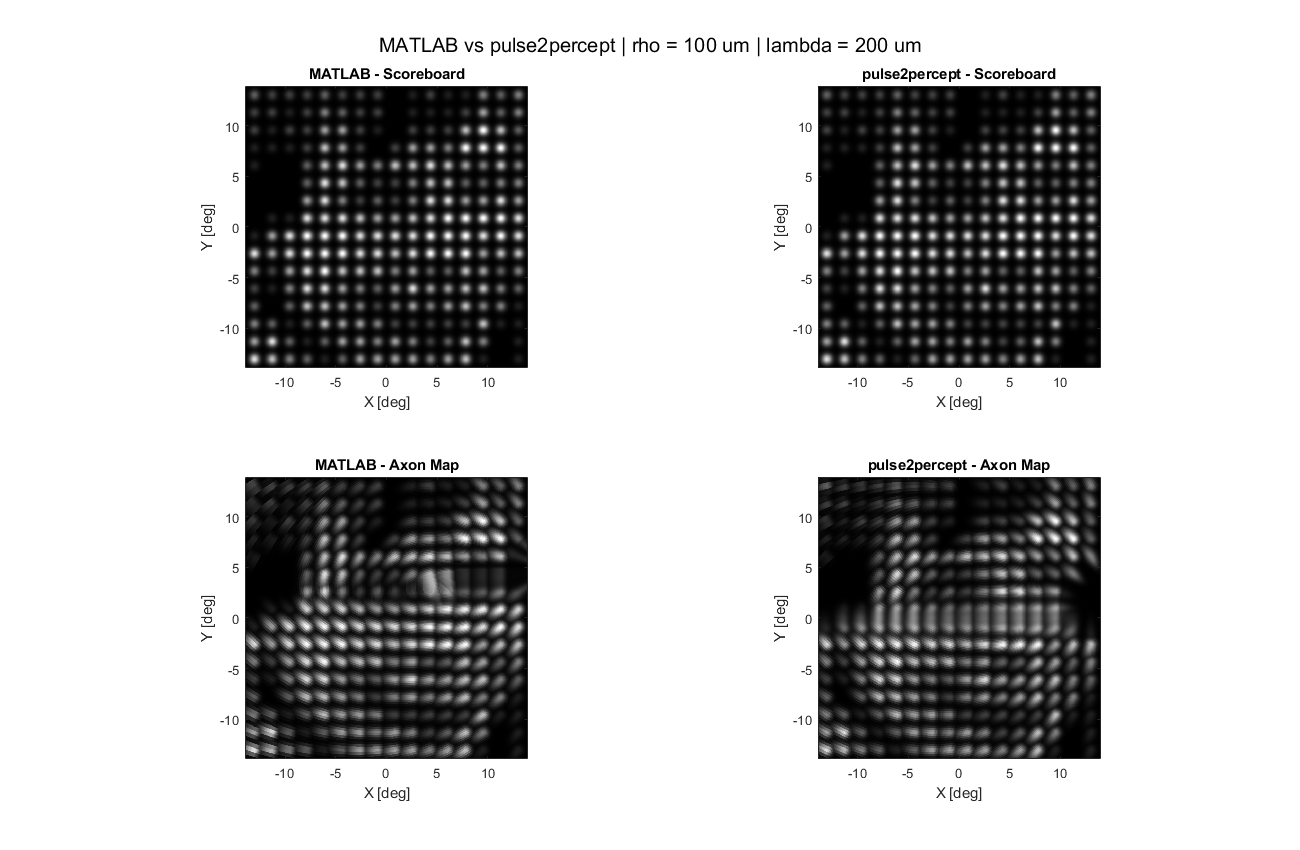



% ------------------------------------------------------------
% 7. Load Python results into MATLAB
% ------------------------------------------------------------

p2pResults = load(outputMatFile);

requiredFields = { ...
    'p2p_score_data', ...
    'p2p_axon_data', ...
    'p2p_x', ...
    'p2p_y', ...
    'p2p_version'};

for k = 1:numel(requiredFields)
    if ~isfield(p2pResults, requiredFields{k})
        error('Missing variable in Python output MAT-file: %s', ...
            requiredFields{k});
    end
end

% ------------------------------------------------------------
% 8. Convert Python results to MATLAB arrays
% ------------------------------------------------------------

p2pSBraw = double(p2pResults.p2p_score_data);
p2pAxonRaw = double(p2pResults.p2p_axon_data);

p2pX = double(p2pResults.p2p_x(:));
p2pY = double(p2pResults.p2p_y(:));
%% 9.7 Resample pulse2percept results onto MATLAB output grid

% MATLAB comparison grid.
xCompare = sbMat10.xr;
yCompare = sbMat10.yr;

[Xq, Yq] = meshgrid(xCompare, yCompare);

% P2P axes must be sorted in ascending order for interp2.
[p2pX, ix] = sort(p2pX, 'ascend');
[p2pY, iy] = sort(p2pY, 'ascend');

p2pSBraw = p2pSBraw(iy, ix);
p2pAxonRaw = p2pAxonRaw(iy, ix);

% Interpolate both P2P maps onto the exact MATLAB grid.
p2pSB = interp2(p2pX, p2pY, p2pSBraw, ...
                Xq, Yq, 'linear', 0);

p2pAxon = interp2(p2pX, p2pY, p2pAxonRaw, ...
                  Xq, Yq, 'linear', 0);


%% 9.8 Retrieve MATLAB model outputs

matSB = double(sbMat10.P);
matAxon = double(axMat10.Paxon);

% Ensure that the MATLAB Axon Map uses the comparison grid.
if ~isequal(size(matAxon), size(matSB)) || ...
   ~isequal(axMat10.xr(:), sbMat10.xr(:)) || ...
   ~isequal(axMat10.yr(:), sbMat10.yr(:))

    [xAx, ixAx] = sort(axMat10.xr(:), 'ascend');
    [yAx, iyAx] = sort(axMat10.yr(:), 'ascend');

    matAxonSorted = matAxon(iyAx, ixAx);

    matAxon = interp2(xAx, yAx, matAxonSorted, ...
                      Xq, Yq, 'linear', 0);
end


%% 9.9 Normalize the maps for visual comparison

% Important:
% P2P uses current amplitudes in uA.
% MATLAB models use normalized Scoreboard brightness.
%
% Each map is therefore normalized independently to compare
% spatial distribution and phosphene morphology.

normalizeMap = @(M) M ./ max(max(M(:)), eps);

matSBNorm = normalizeMap(matSB);
p2pSBNorm = normalizeMap(p2pSB);

matAxonNorm = normalizeMap(matAxon);
p2pAxonNorm = normalizeMap(p2pAxon);

p2pSBNorm = flipud(p2pSBNorm);
p2pAxonNorm = flipud(p2pAxonNorm);

%% 9.10 Calculate comparison metrics
% Verify matrix dimensions
assert(isequal(size(matSBNorm), size(p2pSBNorm)), ...
    'Scoreboard matrices must have identical dimensions.');

assert(isequal(size(matAxonNorm), size(p2pAxonNorm)), ...
    'Axon Map matrices must have identical dimensions.');

% Scoreboard comparison.
diffSB = matSBNorm - p2pSBNorm;

rmseSB = sqrt(mean(diffSB(:).^2));
maeSB = mean(abs(diffSB(:)));

% Axon Map comparison.
diffAxon = matAxonNorm - p2pAxonNorm;

rmseAxon = sqrt(mean(diffAxon(:).^2));
maeAxon = mean(abs(diffAxon(:)));


% Correlation coefficients.
Rsb = corrcoef(matSBNorm(:), p2pSBNorm(:));
Raxon = corrcoef(matAxonNorm(:), p2pAxonNorm(:));

corrSB = Rsb(1,2);
corrAxon = Raxon(1,2);


%% 9.11 Display four model outputs

figure('Name', 'Part 9 - MATLAB vs pulse2percept', ...
       'Color', 'w', ...
       'Position', [100 100 1300 850]);

% 1. MATLAB Scoreboard
ax1 = subplot(2,2,1);

imagesc(ax1, [xCompare(1) xCompare(end)], ...
             [yCompare(1) yCompare(end)], matSBNorm);

set(ax1, 'YDir', 'normal', 'CLim', [0 1], 'Color', 'k');
colormap(ax1, gray(256));
axis(ax1, 'image');

title(ax1, 'MATLAB - Scoreboard');
xlabel(ax1, 'X [deg]');
ylabel(ax1, 'Y [deg]');


% 2. pulse2percept Scoreboard
ax2 = subplot(2,2,2);

imagesc(ax2, [xCompare(1) xCompare(end)], ...
             [yCompare(1) yCompare(end)], p2pSBNorm);
set(ax2, 'YDir', 'normal', 'CLim', [0 1], 'Color', 'k');
colormap(ax2, gray(256));
axis(ax2, 'image');

title(ax2, 'pulse2percept - Scoreboard');
xlabel(ax2, 'X [deg]');
ylabel(ax2, 'Y [deg]');


% 3. MATLAB Axon Map
ax3 = subplot(2,2,3);

imagesc(ax3, [xCompare(1) xCompare(end)], ...
             [yCompare(1) yCompare(end)], matAxonNorm);

set(ax3, 'YDir', 'normal', 'CLim', [0 1], 'Color', 'k');
colormap(ax3, gray(256));
axis(ax3, 'image');

title(ax3, 'MATLAB - Axon Map');
xlabel(ax3, 'X [deg]');
ylabel(ax3, 'Y [deg]');


% 4. pulse2percept Axon Map
ax4 = subplot(2,2,4);

imagesc(ax4, [xCompare(1) xCompare(end)], ...
             [yCompare(1) yCompare(end)], p2pAxonNorm);
set(ax4, 'YDir', 'normal', 'CLim', [0 1], 'Color', 'k');
colormap(ax4, gray(256));
axis(ax4, 'image');

title(ax4, 'pulse2percept - Axon Map');
xlabel(ax4, 'X [deg]');
ylabel(ax4, 'Y [deg]');

sgtitle(sprintf( ...
    'MATLAB vs pulse2percept | rho = %.0f um | lambda = %.0f um', ...
    rhoUm, lambdaUm));

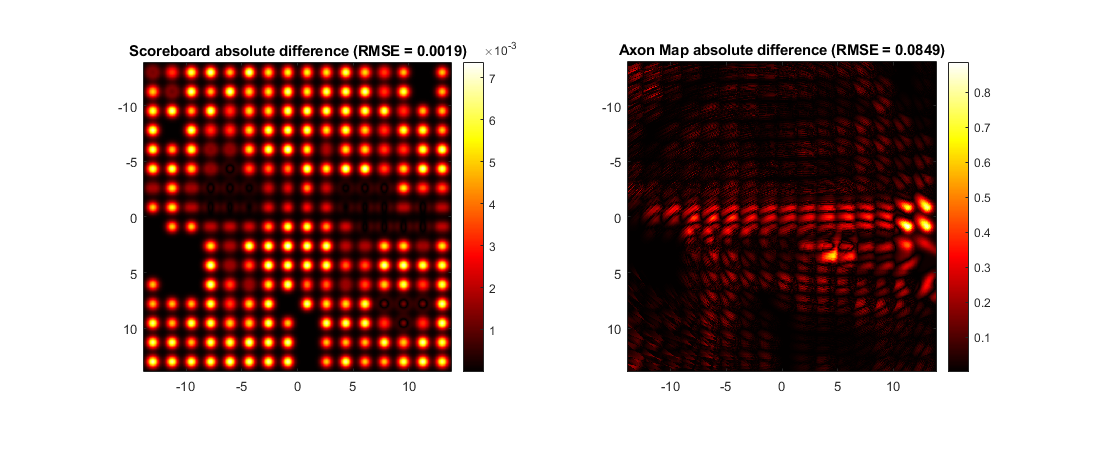



%% 9.12 Display absolute difference maps

figure('Name', 'Part 9 - Model differences', ...
       'Color', 'w', ...
       'Position', [150 150 1100 450]);

% Scoreboard difference.
ax1 = subplot(1,2,1);

imagesc(ax1, [xCompare(1) xCompare(end)], ...
             [yCompare(1) yCompare(end)], abs(diffSB));

set(ax1, 'YDir', 'reverse', 'Color', 'k');
colormap(ax1, hot(256));
axis(ax1, 'image');
colorbar(ax1);

title(ax1, sprintf('Scoreboard absolute difference (RMSE = %.4f)', rmseSB));


% Axon map difference.
ax2 = subplot(1,2,2);

imagesc(ax2, [xCompare(1) xCompare(end)], ...
             [yCompare(1) yCompare(end)], abs(diffAxon));

set(ax2, 'YDir', 'reverse', 'Color', 'k');
colormap(ax2, hot(256));
axis(ax2, 'image');
colorbar(ax2);

title(ax2, sprintf('Axon Map absolute difference (RMSE = %.4f)', rmseAxon));


%% 9.13 Print comparison results
fprintf('\nCommon parameters:\n');


Common parameters:


fprintf('Grid size           : %d x %d\n', gridSize(1), gridSize(2));

Grid size           : 16 x 16


fprintf('Electrode pitch     : %.1f x %.1f um\n', pitchUm(1), pitchUm(2));

Electrode pitch     : 500.0 x 500.0 um


fprintf('rho                 : %.2f um\n', rhoUm);

rho                 : 100.00 um


fprintf('lambda              : %.2f um\n', lambdaUm);

lambda              : 200.00 um


fprintf('Output resolution   : %.1f pixels/deg\n', comparisonMapRes);

Output resolution   : 30.0 pixels/deg


fprintf('Maximum current     : %.1f uA\n', max(currentsUA));

Maximum current     : 106.7 uA



fprintf('\nScoreboard comparison:\n');


Scoreboard comparison:


fprintf('MATLAB maximum      : %.6f\n', max(matSB(:)));

MATLAB maximum      : 0.886811


fprintf('P2P maximum         : %.6f\n', max(p2pSB(:)));

P2P maximum         : 106.567629


fprintf('RMSE                : %.6f\n', rmseSB);

RMSE                : 0.001923


fprintf('MAE                 : %.6f\n', maeSB);

MAE                 : 0.001308


fprintf('Correlation         : %.6f\n', corrSB);

Correlation         : 0.999972



fprintf('\nAxon Map comparison:\n');


Axon Map comparison:


fprintf('MATLAB maximum      : %.6f\n', max(matAxon(:)));

MATLAB maximum      : 0.886648


fprintf('P2P maximum         : %.6f\n', max(p2pAxon(:)));

P2P maximum         : 106.395352


fprintf('RMSE                : %.6f\n', rmseAxon);

RMSE                : 0.084935


fprintf('MAE                 : %.6f\n', maeAxon);

MAE                 : 0.047651


fprintf('Correlation         : %.6f\n', corrAxon);

Correlation         : 0.888824



fprintf('\nComparison completed.\n');


Comparison completed.


Parte 10 

======================================================================

##                                        FUNCTIONS

                  (they must stay at the end of the file, after all the script code)

 ======================================================================

### *create_electrode_grid*  Compute the center positions of an electrode array.

   [x, y, coords] = create_electrode_grid(nRows, nCols, pitchX, pitchY, layout, centerGrid)

   Inputs

     nRows      - number of electrodes along the vertical axis (rows)

     nCols      - number of electrodes along the horizontal axis (columns)

     pitchX     - center-to-center spacing along X [um]

     pitchY     - center-to-center spacing along Y [um]

     layout     - "square" or "hexagonal" (odd rows shifted by pitchX/2)

     centerGrid - true  -> grid centered on the origin (0,0)

                  false -> first electrode placed at the origin

   Outputs

     x, y       - column vectors (nElec x 1) of electrode centers [um],

                  numbered row by row (left to right, top to bottom)

     coords     - table with columns Index, X_um, Y_um

   Coordinate convention: Y grows with the row index (image convention,

   Y pointing DOWN). When plotting, call axis(ax, 'ij') so that electrode

   #1 appears at the top-left.

function [x, y, coords] = create_electrode_grid(nRows, nCols, pitchX, pitchY, layout, centerGrid)
    % ---- Input validation: fail early with a clear message ----
    assert(nRows >= 1 && nCols >= 1 && ...
           nRows == round(nRows) && nCols == round(nCols), ...
           "nRows and nCols must be positive integers.");
    assert(pitchX > 0 && pitchY > 0, "Pitches must be strictly positive.");
    assert(ismember(layout, ["square", "hexagonal"]), ...
           "layout must be ""square"" or ""hexagonal"".");

    % ---- Grid indices ----
    % meshgrid builds one (column, row) index pair for every electrode.
    % Indices start at 0, so the first electrode sits at the origin.
    [colIdx, rowIdx] = meshgrid(0:nCols-1, 0:nRows-1);

    % ---- Scale indices into physical positions [um] ----
    x = colIdx * pitchX;
    y = rowIdx * pitchY;

    % ---- Hexagonal layout: shift odd rows by half a pitch along X ----
    if layout == "hexagonal"
        oddRows = mod(rowIdx, 2) == 1;       % logical mask of odd rows
        x(oddRows) = x(oddRows) + pitchX/2;  % half-pitch offset
    end

    % ---- Flatten into column vectors, one entry per electrode ----
    % MATLAB's (:) reads a matrix column by column, so we transpose first
    % (.') to obtain a row-by-row numbering (left to right, top to bottom).
    x = x.';  x = x(:);
    y = y.';  y = y(:);

    % ---- Optionally recenter the whole array on the origin ----
    if centerGrid
        x = x - (max(x) + min(x)) / 2;
        y = y - (max(y) + min(y)) / 2;
    end

    % ---- Table of all electrode positions ----
    nElec  = numel(x);
    coords = table((1:nElec)', x, y, ...
                   'VariableNames', {'Index', 'X_um', 'Y_um'});
end

### *place_grid_on_retina*  Rotate and translate an electrode grid onto the retina grid.

   [xDeg, yDeg] = place_grid_on_retina(x, y, centerOffset, tiltDeg, umPerDeg)

   Inputs

     x, y         - electrode centers [um] from create_electrode_grid,

                    centered on the array center (centerGrid = true)

     centerOffset - [x y] position of the array center relative to the

                    fovea [um]; X to the right, Y up

     tiltDeg      - rotation of the array around its own center [deg],

                    positive = counter-clockwise

     umPerDeg     - retinal magnification: micrometers per degree of

                    visual angle (288 um/deg)

   Outputs

     xDeg, yDeg   - electrode centers in the retina grid frame [deg],

                    fovea at the origin, Y pointing up

   Steps: (1) flip Y, (2) rotate, (3) translate, (4) convert um -> deg.

function [xDeg, yDeg] = place_grid_on_retina(x, y, centerOffset, tiltDeg, umPerDeg)
    % ---- 1. Match the retina convention (Y up) ----
    % create_electrode_grid uses the image convention (Y down, electrode #1
    % at the top-left). Negating y keeps electrode #1 at the top-left on
    % the retina grid, whose Y axis points up.
    y = -y;

    % ---- 2. Rotate around the array center (the local origin) ----
    % Standard 2-D rotation matrix applied to every electrode.
    xRot = x * cosd(tiltDeg) - y * sind(tiltDeg);
    yRot = x * sind(tiltDeg) + y * cosd(tiltDeg);

    % ---- 3. Translate: move the array center to its position vs. the fovea ----
    xRot = xRot + centerOffset(1);
    yRot = yRot + centerOffset(2);

    % ---- 4. Convert micrometers to degrees of visual angle ----
    xDeg = xRot / umPerDeg;
    yDeg = yRot / umPerDeg;
end

### *draw_retina_grid*  Draw a polar reference grid of the retina (no axon fibers).

   draw_retina_grid(ax, maxEcc, eccStep, angStep, odCenter, odSize, foveaRadius)

   The grid is expressed in degrees of visual angle and is centered on the fovea, which sits at the origin (0, 0).

   Inputs

     ax          - axes handle to draw into

     maxEcc      - outermost eccentricity circle [deg]

     eccStep     - spacing between concentric circles [deg]

     angStep     - angle between radial lines [deg]

     odCenter    - optic disc center [x y] in degrees

     odSize      - optic disc [width height] in degrees

     foveaRadius - radius of the fovea marker [deg]

   Convention: X points to the right, Y points up (standard Cartesian view).

function draw_retina_grid(ax, maxEcc, eccStep, angStep, odCenter, odSize, foveaRadius)
    % ---- Input validation: fail early with a clear message ----
    assert(maxEcc > 0 && eccStep > 0 && eccStep <= maxEcc, ...
           "Eccentricities must satisfy 0 < eccStep <= maxEcc.");
    assert(angStep > 0 && angStep <= 180, "angStep must be in ]0, 180].");

    hold(ax, 'on');
    gridColor = [0.65 0.65 0.65];   % light gray for all grid lines
    t = linspace(0, 2*pi, 361);     % angles used to draw circles / ellipses

    % ---- Concentric circles (constant eccentricity) ----
    eccList = eccStep:eccStep:maxEcc;   % e.g. 10, 20, 30 deg
    for e = eccList
        % x = e*cos(t) and y = e*sin(t) describe a circle of radius e
        plot(ax, e*cos(t), e*sin(t), 'Color', gridColor, 'LineWidth', 0.75);
    end

    % ---- Radial lines (constant polar angle) ----
    % Each line goes from the fovea (origin) to the outermost circle.
    % With angStep = 45, the horizontal and vertical axes are included.
    for a = 0:angStep:(360 - angStep)
        plot(ax, [0, maxEcc*cosd(a)], [0, maxEcc*sind(a)], ...
             'Color', gridColor, 'LineWidth', 0.75);
    end

    % ---- Eccentricity labels along the left half of the horizontal axis ----
    % The white background hides the grid line behind the text.
    for e = eccList
        text(ax, -e, 0, sprintf('%g%c', e, char(176)), ...
             'HorizontalAlignment', 'center', ...
             'VerticalAlignment',   'middle', ...
             'BackgroundColor',     'w', ...
             'Margin',              1, ...
             'FontSize',            8);
    end

    % ---- Optic disc: filled gray ellipse ----
    % Ellipse centered on odCenter, with semi-axes = size / 2.
    odX = odCenter(1) + (odSize(1)/2) * cos(t);
    odY = odCenter(2) + (odSize(2)/2) * sin(t);
    fill(ax, odX, odY, [0.85 0.85 0.85], 'EdgeColor', 'none');

    % ---- Fovea: white disc at the origin, drawn last so it hides the lines ----
    fill(ax, foveaRadius*cos(t), foveaRadius*sin(t), 'w', ...
         'EdgeColor', gridColor, 'LineWidth', 0.75);

    % ---- Axes appearance ----
    axis(ax, 'equal');                                  % same scale on X and Y -> true circles
    axis(ax, [-maxEcc maxEcc -maxEcc maxEcc] * 1.05);   % small margin around the grid
    axis(ax, 'off');                                    % no ticks, the grid itself is the reference
end

### sample_image_on_grid  Mean image intensity at each electrode (box filter).

   [I, rowE, colE, pxPerDeg, filtSize] = sample_image_on_grid(img, xDeg, yDeg, ...

                              pitchXDeg, pitchYDeg, widthDeg, heightDeg)

   The image is stretched over the field of view covered by the grid (widthDeg x heightDeg).

    Each electrode is placed on the nearest pixel, and its intensity is the mean of the image over a box of size "electrode spacing", read at that pixel.

   Inputs

     img        - grayscale image (H x W), double, values in [0, 1]

     xDeg,yDeg  - electrode centers [deg], origin = grid center, Y UP

     pitchXDeg  - horizontal electrode spacing [deg]

     pitchYDeg  - vertical electrode spacing [deg]

     widthDeg   - width  of the field of view covered by the image [deg]

     heightDeg  - height of the field of view covered by the image [deg]

   Outputs

     I          - mean intensity at each electrode (nElec x 1), in [0, 1]

     rowE,colE  - pixel row / column of each electrode

     pxPerDeg   - [horizontal vertical] image resolution [pixel/deg]

     filtSize   - [height width] of the box filter [pixels] (odd numbers)


function [I, rowE, colE, pxPerDeg, filtSize] = sample_image_on_grid(img, xDeg, yDeg, pitchXDeg, pitchYDeg, widthDeg, heightDeg)
    [H, W] = size(img);

    % ---- 1. Image resolution in pixels per degree ----
    % Image size in pixels divided by the field of view in degrees.
    pxPerDegX = W / widthDeg;
    pxPerDegY = H / heightDeg;
    pxPerDeg  = [pxPerDegX, pxPerDegY];

    % ---- 2. Electrode position in pixels (rounded to the nearest pixel) ----
    % The image center is the grid center. Rows grow downward, Y grows upward.
    cx   = (W + 1) / 2;
    cy   = (H + 1) / 2;
    colE = round(cx + xDeg(:) * pxPerDegX);
    rowE = round(cy - yDeg(:) * pxPerDegY);
    colE = min(max(colE, 1), W);     % safety: stay inside the image
    rowE = min(max(rowE, 1), H);

    % ---- 3. Box filter size = electrode spacing converted to pixels ----
    % Rounded to the NEAREST ODD integer so the window is centered on a pixel.
    toOdd = @(n) max(1, 2 * round((n - 1) / 2) + 1);
    nw = toOdd(pitchXDeg * pxPerDegX);   % filter width  [px]
    nh = toOdd(pitchYDeg * pxPerDegY);   % filter height [px]
    filtSize = [nh, nw];

    % ---- 4. Mean filter (box kernel convolved with the image) ----
    % K sums to 1, so each output pixel is the mean of the nh x nw pixels
    % around it. Outside the image the pixels count as 0.
    K = ones(nh, nw) / (nh * nw);
    filtered = conv2(img, K, 'same');          % or: filtered = iconvolve(K, img);

    % ---- 5. Read the filtered image at each electrode pixel ----
    I = filtered(sub2ind([H, W], rowE, colE));
end

### *render_phosphenes*  Draw one Gaussian phosphene per electrode on a black background.

   [P, xg, yg] = render_phosphenes(xDeg, yDeg, amp, sigmaDeg, widthDeg, heightDeg, outRes)

   Each phosphene is a 2-D Gaussian centered on its electrode, whose peak value is the brightness of that electrode

   Overlapping phosphenes add up, and the result is clipped to 1.

   Inputs

     xDeg,yDeg  - electrode centers [deg], origin = grid center, Y UP

     amp        - brightness of each electrode (nElec x 1), in [0, 1]

     sigmaDeg   - standard deviation of the Gaussian [deg]

     widthDeg   - width  of the displayed field of view [deg]

     heightDeg  - height of the displayed field of view [deg]

     outRes   - resolution of the output image [pixel/deg]

   Outputs

     P          - phosphene image (Ny x Nx), values in [0, 1]; row 1 is the TOP

     xg, yg     - coordinate vectors of the columns / rows [deg]

function [P, xg, yg] = render_phosphenes(xDeg, yDeg, amp, rho, widthDeg, heightDeg, outRes)

    Nx = round(widthDeg  * outRes);
    Ny = round(heightDeg * outRes);

    xg = linspace(-widthDeg/2,  widthDeg/2,  Nx);   % 1 x Nx, left to right
    yg = linspace( heightDeg/2, -heightDeg/2, Ny);  % 1 x Ny, top to bottom

    % A 2-D Gaussian is separable: exp(-(dx^2+dy^2)/(2s^2)) = gx(dx) * gy(dy).
    % So the sum over all electrodes is a single matrix product (no loop).
    Gx = exp(-(xg - xDeg(:)).^2 / (2 * rho^2));   % nElec x Nx
    Gy = exp(-(yg - yDeg(:)).^2 / (2 * rho^2));   % nElec x Ny

    P = Gy' * (amp(:) .* Gx);   % (Ny x nElec) * (nElec x Nx) = Ny x Nx
    P = min(P, 1);              % clip where phosphenes overlap
end

### *jansonius_phi* calculate the trajectory of each axon

It takes phi0 the initiale angle and r the length of the trajectory

function phi = jansonius_phi(phi0, r)
    % Original radial reference distance.
    r0 = 4;
    % Calculate b and c.
    b = jansonius_b(phi0);
    c = jansonius_c(phi0);
    % Jansonius angular trajectory.
    phi = phi0 + b * (r - r0).^c;
end


function b = jansonius_b(phi0)
    % Fold angles above 180 degrees.
    if phi0 > 180
        phi0 = 360 - phi0;
    end

    betaS = -1.9;
    betaI = 0.7;
    
    if phi0 > 0
        % Superior fibers.
        b = exp(betaS + 3.9 * ...
            tanh(-(phi0 - 121) / 14));
    else
        % Inferior fibers.
        b = -exp(betaI + 1.5 * ...
            tanh(-(-phi0 - 90) / 25));
    end
end


function c = jansonius_c(phi0)

    % Fold angles above 180 degrees.
    if phi0 > 180
        phi0 = 360 - phi0;
    end

    if phi0 > 0
        % Superior fibers.
        c = 1.9 + 1.4 * ...
            tanh((phi0 - 121) / 14);
    else
        % Inferior fibers.
        c = 1.0 + 0.5 * ...
            tanh((-phi0 - 90) / 25);
    end
end

### *scoreboard_model*  Image to phosphenes in the retina frame (scoreboard model).

  out = scoreboard_model(img, gridSize, pitchUm, dropoutPercent, retinaPos, rhoUm, Name, Value, ...)

  Pipeline (same as Parts 1-5):

    1. electrode grid [um], dropout mask

    2. image mapped on the grid field of view, box-filter mean per electrode

    3. quantization -> current -> brightness B = a*C^b (normalized)

    4. grid placed on the retina (rotation + translation), um -> deg

    5. one Gaussian phosphene per electrode, sigma = rho

  Optional Name-Value pairs (defaults in brackets)

    'Layout'           "square" or "hexagonal"             ["square"]

    'NLevels'          number of gray levels (>= 2)        [10]

    'Cmax'             current of the brightest level [uA] [120]

    'BrightnessA'      a in B = a*C^b                      [1.24]

    'BrightnessB'      b in B = a*C^b                      [1.02]

    'UmPerDeg'         retinal magnification [um/deg]      [288]

    'MaxEcc'           retina radius shown [deg]           [30]

    'OutRes'           output resolution [pixel/deg]       [60]

    'DropoutSeed'      seed of the dropout selection       [42]

    'CropToGridAspect' center-crop the image to the grid aspect ratio [true]

    'PlaceOnRetina'    true : electrodes are rotated / translated with retinaPos and

                              the phosphenes are drawn in the retina frame

                              (field of view = 2*MaxEcc x 2*MaxEcc, fovea at the origin)

                       false: retinaPos is ignored; the phosphenes are drawn in the

                              frame of the grid, on an image the size of the grid

                              field of view (as in Part 4)                    [true]

  Output struct "out"

    P, xr, yr          phosphene image (row 1 = top) and axes [deg]

                       (retina frame or grid frame, see 'PlaceOnRetina')

    xRet, yRet         electrode centers in the displayed frame [deg]

    Bn, Bn_retina      normalized brightness (after dropout / after retina mask)

    dropoutMask        true = functional electrode

    I, Iq, C           mean intensity, quantized level, current [uA]

    rhoDeg, umPerDeg, maxEcc, widthDeg, heightDeg, img (cropped gray image)

function out = scoreboard_model(img, gridSize, pitchUm, dropoutPercent, retinaPos, rhoUm, varargin)

    % ---- Options ----
    p = inputParser;
    addParameter(p, 'Layout',           "square", @(v) isstring(v) || ischar(v));
    addParameter(p, 'NLevels',          10,   @(v) isnumeric(v) && isscalar(v) && v >= 2 && v == round(v));
    addParameter(p, 'Cmax',             120,  @(v) isnumeric(v) && isscalar(v) && v > 0);
    addParameter(p, 'BrightnessA',      1.24, @(v) isnumeric(v) && isscalar(v));
    addParameter(p, 'BrightnessB',      1.02, @(v) isnumeric(v) && isscalar(v));
    addParameter(p, 'UmPerDeg',         288,  @(v) isnumeric(v) && isscalar(v) && v > 0);
    addParameter(p, 'MaxEcc',           30,   @(v) isnumeric(v) && isscalar(v) && v > 0);
    addParameter(p, 'OutRes',           60,   @(v) isnumeric(v) && isscalar(v) && v > 0);
    addParameter(p, 'DropoutSeed',      42,   @(v) isnumeric(v) && isscalar(v));
    addParameter(p, 'CropToGridAspect', true, @(v) islogical(v) || isnumeric(v));
    addParameter(p, 'PlaceOnRetina',    true, @(v) islogical(v) || isnumeric(v));
    parse(p, varargin{:});
    o = p.Results;

    % ---- Input validation: fail early with a clear message ----
    assert(numel(gridSize) == 2 && all(gridSize >= 1) && all(gridSize == round(gridSize)), ...
           "gridSize must be [nRows nCols] (positive integers).");
    assert(any(numel(pitchUm) == [1 2]) && all(pitchUm > 0), ...
           "pitchUm must be a positive scalar or [pitchX pitchY].");
    assert(dropoutPercent >= 0 && dropoutPercent <= 100, ...
           "dropoutPercent must be between 0 and 100.");
    assert(any(numel(retinaPos) == [2 3]), ...
           "retinaPos must be [x y] or [x y tilt].");
    assert(isscalar(rhoUm) && rhoUm > 0, "rhoUm must be a positive scalar.");

    nRows = gridSize(1);   nCols = gridSize(2);
    if isscalar(pitchUm), pitchUm = [pitchUm pitchUm]; end
    pitchX = pitchUm(1);   pitchY = pitchUm(2);

    centerOffset = retinaPos(1:2);
    tiltDeg = 0;
    if numel(retinaPos) == 3, tiltDeg = retinaPos(3); end

    umPerDeg = o.UmPerDeg;
    maxEcc   = o.MaxEcc;

    % ---- 1. Electrode grid and dropout mask ----
    [x, y] = create_electrode_grid(nRows, nCols, pitchX, pitchY, string(o.Layout), true);
    nElec  = numel(x);

    % Local random stream: the global RNG state is not modified.
    stream      = RandStream('twister', 'Seed', o.DropoutSeed);
    nFailed     = round(nElec * dropoutPercent / 100);
    failedIdx   = randperm(stream, nElec, nFailed);
    dropoutMask = true(nElec, 1);
    dropoutMask(failedIdx) = false;

    % ---- 2. Image -> gray in [0, 1] ----
    if ischar(img) || isstring(img)
        img = imread(char(img));
    end
    if isinteger(img)
        img = double(img) / double(intmax(class(img)));
    else
        img = double(img);
    end
    if size(img, 3) >= 3
        img = 0.299*img(:,:,1) + 0.587*img(:,:,2) + 0.114*img(:,:,3);
    else
        img = img(:,:,1);
    end

    % ---- 3. Grid in the image frame (deg), field of view of the grid ----
    xDeg =  x / umPerDeg;
    yDeg = -y / umPerDeg;
    pitchXDeg = pitchX / umPerDeg;
    pitchYDeg = pitchY / umPerDeg;

    widthDeg  = (max(xDeg) - min(xDeg)) + pitchXDeg;
    heightDeg = (max(yDeg) - min(yDeg)) + pitchYDeg;

    if o.CropToGridAspect
        [H, W] = size(img);
        target = widthDeg / heightDeg;
        if W / H > target                       % image too wide -> crop columns
            Wn  = round(H * target);
            c0  = floor((W - Wn) / 2) + 1;
            img = img(:, c0:c0+Wn-1);
        else                                    % image too tall -> crop rows
            Hn  = round(W / target);
            r0  = floor((H - Hn) / 2) + 1;
            img = img(r0:r0+Hn-1, :);
        end
    end

    % ---- 4. Mean intensity, quantization, current, brightness ----
    I  = sample_image_on_grid(img, xDeg, yDeg, pitchXDeg, pitchYDeg, widthDeg, heightDeg);
    Iq = round(I * (o.NLevels - 1)) / (o.NLevels - 1);

    C    = Iq * o.Cmax;                         % current [uA]
    B    = o.BrightnessA * C.^o.BrightnessB;    % brightness B = a*C^b
    Bmax = o.BrightnessA * o.Cmax^o.BrightnessB;
    Bn   = B / Bmax;                            % normalized to [0, 1]
    Bn(~dropoutMask) = 0;                       % failed electrodes: no phosphene

    rhoDeg = rhoUm / umPerDeg;

    if o.PlaceOnRetina
        % ---- 5a. Retina frame: place the grid, mask the outside, render ----
        [xRet, yRet] = place_grid_on_retina(x, y, centerOffset, tiltDeg, umPerDeg);

        Bn_retina = Bn;
        Bn_retina(hypot(xRet, yRet) > maxEcc) = 0;
        nOutside = nnz(hypot(xRet, yRet) > maxEcc);
        if nOutside > 0
            warning("scoreboard_model:outsideRetina", ...
                    "%d electrodes are outside the retina circle (%g deg) and are masked.", ...
                    nOutside, maxEcc);
        end

        % Gaussian phosphenes (sigma = rho) on the retina canvas
        [P, xr, yr] = render_phosphenes(xRet, yRet, Bn_retina, rhoDeg, ...
                                        2*maxEcc, 2*maxEcc, o.OutRes);
    else
        % ---- 5b. Grid frame: no rotation, no translation, no retina mask ----
        % The image has the size of the grid field of view (as in Part 4).
        xRet      = xDeg;
        yRet      = yDeg;
        Bn_retina = Bn;

        [P, xr, yr] = render_phosphenes(xRet, yRet, Bn_retina, rhoDeg, ...
                                        widthDeg, heightDeg, o.OutRes);
    end

    % ---- Output ----
    out = struct('P', P, 'xr', xr, 'yr', yr, ...
                 'xRet', xRet, 'yRet', yRet, ...
                 'Bn', Bn, 'Bn_retina', Bn_retina, 'dropoutMask', dropoutMask, ...
                 'I', I, 'Iq', Iq, 'C', C, ...
                 'rhoDeg', rhoDeg, 'umPerDeg', umPerDeg, 'maxEcc', maxEcc, ...
                 'widthDeg', widthDeg, 'heightDeg', heightDeg, 'img', img, ...
                 'placedOnRetina', logical(o.PlaceOnRetina));
end



### *axon_map_model*  Image to percept with axonal activation (Beyeler 2019 axon map).

  out = axon_map_model(img, gridSize, pitchUm, dropoutPercent, retinaPos, rhoUm, lambdaUm, Name, Value, ...)

  Same inputs as scoreboard_model, plus lambdaUm. The electrode drive

  (grid, dropout, quantization, brightness, placement) comes from

  scoreboard_model, so all its Name-Value options are accepted here too

  (except 'OutRes', replaced by 'MapRes').

  For each possible soma (every retinal pixel, assigned to its nearest axon):

    I(soma) = max over upstream axon points i of

              [ sum_e amp_e * exp(-d_e(i)^2 / (2 rho^2)) ] * decay(s(i,soma))

    decay(s) = exp(-s^2/(2 lambda^2))    ("gaussian": current pulse2percept, default)

             = exp(-s/lambda)            ("exponential": older pulse2percept docs)

  Additional Name-Value pairs (defaults in brackets)

    'MapRes'      output resolution [pixel/deg]                          [20]

    'PlaceOnRetina'  true : result in the retina frame (2*MaxEcc square).

                     false: the axon map is still computed on the retina (the axon

                            geometry needs it), then resampled in the frame of the

                            grid (rotation / translation undone) on an image the

                            size of the grid field of view, like scoreboard_model. [true]

    'NAxons'      number of axons, phi0 in [-180, 180]                   [1000]

    'OdCenter'    optic disc center relative to the fovea [deg]          [14 2.4]

    'RStart'      initial distance from the optic disc center [deg]      [4.01]

    'RMax'        safety bound on the radial distance [deg]              [60]

    'DeltaR'      radial increment [deg]                                 [0.1]

    'AxonStep'    arc-length sampling along the axons [deg]              [0.1]

    'MaxSnapDeg'  pixels farther than this from every axon stay black.

                  Inf = every pixel takes its nearest axon, like pulse2percept [Inf]

    'RapheMargin' superior axons stop when y <= RapheMargin, inferior ones when

                  y >= -RapheMargin [deg]. 0 leaves no empty strip at the

                  horizontal meridian (the old hard-coded value was 0.5)       [0]

    'DecayModel'  "gaussian" or "exponential"                            ["gaussian"]

    'MeridianBlend'  std of the Gaussian blend between the superior and the

                  inferior axons across the horizontal meridian [deg]; 0 = off.

                  Inspired by pulse2percept's meridian_blend (default 1); the exact

                  formula below is my own reading, not the original code.        [1]

    'MinAxSensitivity'  gaussian model: axon points whose decay is below this

                  value are ignored (as min_ax_sensitivity in pulse2percept)     [1e-3]

    'UseCache'    save / reuse the sampled trajectories                  [true]

    'CacheFile'   cache file name                    ['axon_sampling_cache_fn.mat']

    'Verbose'     print progress                                         [true]

  Output struct "out"

    Paxon          axonal phosphene image (row 1 = top), NOT clipped to 1

    Pscore         scoreboard image on the same grid (same rho), for comparison

    xr, yr         axes of both images [deg]

    sb             full output of scoreboard_model (electrode positions, brightness, ...)

    rhoDeg, lambdaDeg, nAxonSamples

function out = axon_map_model(img, gridSize, pitchUm, dropoutPercent, retinaPos, rhoUm, lambdaUm, varargin)

    % ---- Options specific to the axon map (the others go to scoreboard_model) ----
    p = inputParser;
    p.KeepUnmatched = true;
    addParameter(p, 'MapRes',     20,   @(v) isnumeric(v) && isscalar(v) && v > 0);
    addParameter(p, 'PlaceOnRetina', true, @(v) islogical(v) || isnumeric(v));
    addParameter(p, 'NAxons',     1000, @(v) isnumeric(v) && isscalar(v) && v >= 2);
    addParameter(p, 'OdCenter',   [14 2.4], @(v) isnumeric(v) && numel(v) == 2);
    addParameter(p, 'RStart',     4.01, @(v) isnumeric(v) && isscalar(v));
    addParameter(p, 'RMax',       60,   @(v) isnumeric(v) && isscalar(v));
    addParameter(p, 'DeltaR',     0.1,  @(v) isnumeric(v) && isscalar(v) && v > 0);
    addParameter(p, 'AxonStep',   0.1,  @(v) isnumeric(v) && isscalar(v) && v > 0);
    addParameter(p, 'MaxSnapDeg', Inf,  @(v) isnumeric(v) && isscalar(v) && v > 0);
    addParameter(p, 'RapheMargin', 0,   @(v) isnumeric(v) && isscalar(v) && v >= 0);
    addParameter(p, 'DecayModel', "gaussian", @(v) isstring(v) || ischar(v));
    addParameter(p, 'MeridianBlend', 1, @(v) isnumeric(v) && isscalar(v) && v >= 0);
    addParameter(p, 'MinAxSensitivity', 1e-3, @(v) isnumeric(v) && isscalar(v) && v > 0 && v < 1);
    addParameter(p, 'UseCache',   true, @(v) islogical(v) || isnumeric(v));
    addParameter(p, 'CacheFile',  'axon_sampling_cache_fn.mat', @(v) isstring(v) || ischar(v));
    addParameter(p, 'Verbose',    true, @(v) islogical(v) || isnumeric(v));
    parse(p, varargin{:});
    o = p.Results;

    assert(isscalar(lambdaUm) && lambdaUm > 0, "lambdaUm must be a positive scalar.");
    decayModel = lower(string(o.DecayModel));
    assert(any(decayModel == ["exponential", "gaussian"]), ...
           "DecayModel must be ""exponential"" or ""gaussian"".");

    % ---- Electrode drive: forward the remaining options to scoreboard_model ----
    unmatched = p.Unmatched;
    if isfield(unmatched, 'OutRes'), unmatched = rmfield(unmatched, 'OutRes'); end
    names = fieldnames(unmatched);
    fwd   = cell(1, 2*numel(names));
    for i = 1:numel(names)
        fwd{2*i-1} = names{i};
        fwd{2*i}   = unmatched.(names{i});
    end

    sb = scoreboard_model(img, gridSize, pitchUm, dropoutPercent, retinaPos, rhoUm, ...
                          fwd{:}, 'PlaceOnRetina', true, 'OutRes', o.MapRes);

    maxEcc    = sb.maxEcc;
    rhoDeg    = sb.rhoDeg;
    lambdaDeg = lambdaUm / sb.umPerDeg;

    if o.Verbose
        fprintf('Axon map: rho = %.3f deg, lambda = %.3f deg (%s decay)\n', ...
                rhoDeg, lambdaDeg, decayModel);
    end

    % ---- 1. Axon trajectories, sampled by arc length (cached) ----
    phi0sequence = linspace(-180, 180, o.NAxons);

    cacheMeta = struct('phi0sequence', phi0sequence, 'OdCenter', o.OdCenter, ...
                       'RStart', o.RStart, 'RMax', o.RMax, 'DeltaR', o.DeltaR, ...
                       'RapheMargin', o.RapheMargin, ...
                       'maxEcc', maxEcc, 'AxonStep', o.AxonStep, 'version', 2);

    useCache = false;
    if o.UseCache && isfile(o.CacheFile)
        S = load(o.CacheFile, 'axonSampleX', 'axonSampleY', 'axonSampleS', 'cacheMeta');
        if isfield(S, 'cacheMeta') && isequaln(S.cacheMeta, cacheMeta)
            axonSampleX = S.axonSampleX;
            axonSampleY = S.axonSampleY;
            axonSampleS = S.axonSampleS;
            useCache = true;
            if o.Verbose, fprintf('Axon samples loaded from cache.\n'); end
        end
    end

    if ~useCache
        if o.Verbose, fprintf('Computing %d axon trajectories...\n', o.NAxons); end
        axonSampleX = cell(o.NAxons, 1);
        axonSampleY = cell(o.NAxons, 1);
        axonSampleS = cell(o.NAxons, 1);
        r0 = 4;                                  % Jansonius reference distance [deg]

        for k = 1:o.NAxons
            phi0 = phi0sequence(k);

            % Jansonius et al. 2009 trajectory, vectorized over r
            r   = (o.RStart:o.DeltaR:o.RMax).';
            phi = phi0 + jansonius_b(phi0) * (r - r0).^jansonius_c(phi0);
            xs  = r .* cosd(phi) + o.OdCenter(1);
            ys  = r .* sind(phi) + o.OdCenter(2);

            % Stopping rules: raphe for superior / inferior fibers, retina border
            if phi0 > 0
                stop = (ys <= o.RapheMargin);
            else
                stop = (ys >= -o.RapheMargin) & (r > 10);
            end
            stop = stop | (xs.^2 + ys.^2 > maxEcc^2);
            iEnd = find(stop, 1, 'first');
            if isempty(iEnd), iEnd = numel(r); end
            xs = xs(1:iEnd);   ys = ys(1:iEnd);

            % Resample by arc length from the optic disc end
            s = [0; cumsum(hypot(diff(xs), diff(ys)))];
            [s, u] = unique(s, 'stable');
            xs = xs(u);   ys = ys(u);
            if numel(s) < 2, continue; end

            sQ = (0:o.AxonStep:s(end)).';
            if sQ(end) < s(end), sQ(end+1) = s(end); end
            axonSampleX{k} = interp1(s, xs, sQ, 'linear');
            axonSampleY{k} = interp1(s, ys, sQ, 'linear');
            axonSampleS{k} = sQ;
        end

        if o.UseCache
            save(o.CacheFile, 'axonSampleX', 'axonSampleY', 'axonSampleS', 'cacheMeta');
            if o.Verbose, fprintf('Axon samples saved to: %s\n', o.CacheFile); end
        end
    end

    % ---- 2. Activation of every possible soma along every axon ----
    act = sb.Bn_retina > 0;                       % electrodes able to create a phosphene
    xe  = sb.xRet(act);   ye = sb.yRet(act);   ae = sb.Bn_retina(act);

    % Gaussian model: exp(-d^2/(2 lambda^2)) < MinAxSensitivity beyond this distance
    maxLag = ceil(sqrt(2 * log(1 / o.MinAxSensitivity)) * lambdaDeg / o.AxonStep);
    cellX = cell(o.NAxons, 1);
    cellY = cell(o.NAxons, 1);
    cellI = cell(o.NAxons, 1);
    cellF = cell(o.NAxons, 1);                    % true = superior axon (phi0 > 0)

    for k = 1:o.NAxons
        xF = axonSampleX{k};
        yF = axonSampleY{k};
        s  = axonSampleS{k};
        n  = numel(s);
        if n < 2, continue; end

        % (a) Electrode term: sum of Gaussians (rho) at each axon point (no clipping)
        D2     = (xF - xe.').^2 + (yF - ye.').^2;      % n x nActiveElectrodes
        Iscore = exp(-D2 / (2 * rhoDeg^2)) * ae;

        % (b) Max over the upstream points, weighted by the decay along the axon
        Iax = Iscore;                                  % lag 0: stimulated point = soma
        switch decayModel
            case "exponential"
                % exp(-(sj-si)/lambda) factorizes -> exact O(n) recursion
                g = exp(-diff(s) / lambdaDeg);
                for j = 2:n
                    Iax(j) = max(Iscore(j), Iax(j-1) * g(j-1));
                end
            case "gaussian"
                for lag = 1:min(n-1, maxLag)
                    d = s(1+lag:n) - s(1:n-lag);
                    Iax(1+lag:n) = max(Iax(1+lag:n), ...
                                       Iscore(1:n-lag) .* exp(-d.^2 / (2*lambdaDeg^2)));
                end
        end

        cellX{k} = xF;   cellY{k} = yF;   cellI{k} = Iax;
        cellF{k} = repmat(phi0sequence(k) > 0, n, 1);
    end

    allX   = vertcat(cellX{:});
    allY   = vertcat(cellY{:});
    allI   = vertcat(cellI{:});
    allSup = vertcat(cellF{:});

    % ---- 3. Assign every retinal pixel to its nearest axon point (soma = pixel) ----
    % Same pixel grid as sb.P, so Paxon and Pscore can be compared directly.
    [XM, YM] = meshgrid(sb.xr, sb.yr);
    q   = [XM(:), YM(:)];
    pts = [allX, allY];

    if isempty(pts)
        Paxon = zeros(size(XM));
    else
        % Every pixel takes the value of its nearest axon point (all axons).
        [idx, dist] = nearest_sample(pts, q);
        v = allI(idx);
        v(dist > o.MaxSnapDeg) = 0;                      % no axon close enough

        % Blend across the horizontal meridian: within +-3 sigma of y = 0, mix the
        % value read on the nearest SUPERIOR axon and on the nearest INFERIOR axon,
        % with the Gaussian cumulative weight w(y) = Phi(y / sigma).
        % (My own reading of pulse2percept's 'meridian_blend', not its source code.)
        if o.MeridianBlend > 0
            band = find(abs(q(:,2)) < 3 * o.MeridianBlend);
            if ~isempty(band) && any(allSup) && any(~allSup)
                [iS, dS] = nearest_sample(pts(allSup, :),  q(band, :));
                [iI, dI] = nearest_sample(pts(~allSup, :), q(band, :));

                vSup = allI(allSup);    vSup = vSup(iS);    vSup(dS > o.MaxSnapDeg) = 0;
                vInf = allI(~allSup);   vInf = vInf(iI);    vInf(dI > o.MaxSnapDeg) = 0;

                w = 0.5 * (1 + erf(q(band, 2) / (o.MeridianBlend * sqrt(2))));
                v(band) = w .* vSup + (1 - w) .* vInf;
            end
        end
        Paxon = reshape(v, size(XM));
    end
    Paxon(hypot(XM, YM) > maxEcc) = 0;                       % outside the retina

    if o.Verbose
        fprintf('Axon points: %d | max activation: %.4f | max scoreboard: %.4f\n', ...
                numel(allX), max(Paxon(:)), max(sb.P(:)));
    end

    % ---- 4. Frame of the result: retina or grid ----
    if o.PlaceOnRetina
        Pscore = sb.P;   xr = sb.xr;   yr = sb.yr;
    else
        % Scoreboard computed directly in the grid frame (grid field of view).
        sbGrid = scoreboard_model(img, gridSize, pitchUm, dropoutPercent, retinaPos, rhoUm, ...
                                  fwd{:}, 'PlaceOnRetina', false, 'OutRes', o.MapRes);
        Pscore = sbGrid.P;   xr = sbGrid.xr;   yr = sbGrid.yr;

        % Every grid-frame pixel (u, v) [deg, Y up] is looked up in the retina image
        % with the same transform as place_grid_on_retina (rotation + translation).
        tiltDeg = 0;
        if numel(retinaPos) == 3, tiltDeg = retinaPos(3); end
        cx = retinaPos(1) / sb.umPerDeg;
        cy = retinaPos(2) / sb.umPerDeg;

        [U, V] = meshgrid(xr, yr);
        XR = U*cosd(tiltDeg) - V*sind(tiltDeg) + cx;
        YR = U*sind(tiltDeg) + V*cosd(tiltDeg) + cy;

        PaxonRetina = Paxon;
        % interp2 needs increasing axes: flip the rows (yr goes top to bottom)
        Paxon = interp2(sb.xr, flip(sb.yr), flipud(PaxonRetina), XR, YR, 'linear', 0);
    end

    % ---- Output ----
    out = struct('Paxon', Paxon, 'Pscore', Pscore, 'xr', xr, 'yr', yr, ...
                 'sb', sb, 'rhoDeg', rhoDeg, 'lambdaDeg', lambdaDeg, ...
                 'nAxonSamples', numel(allX), ...
                 'placedOnRetina', logical(o.PlaceOnRetina));
    if ~o.PlaceOnRetina
        out.PaxonRetina = PaxonRetina;   % same map in the retina frame
        out.xrRetina    = sb.xr;
        out.yrRetina    = sb.yr;
    end
end


% nearest_sample  Nearest point of "pts" for every row of "q".
%   [idx, dist] = nearest_sample(pts, q)   pts: n x 2, q: m x 2 (same units)
%   idx  - index in pts of the closest point, dist - distance to it
function [idx, dist] = nearest_sample(pts, q)
    if license('test', 'Statistics_Toolbox') && exist('knnsearch', 'file')
        [idx, dist] = knnsearch(pts, q);               % KD-tree: fast
    else
        idx  = dsearchn(pts, q);                       % base MATLAB: slower
        dist = hypot(pts(idx,1) - q(:,1), pts(idx,2) - q(:,2));
    end
end
